# Antarctic exposure age recalculation code

This code recalculates the exposure age of different sites in Antarctica and generates various plots to visualize the difference.

The code requires that a datafile exists which has the ages stored in it that can be used for plotting. The ages are calculated from the expage calcualtor.

Begin with clearing the workspace

%CAUTION: Uncomment this if it is necessary to clear the workspace, but leave
%commented if there are other variables that are needed
clear, clc, close all

warning('off')


% Load the data needed for this analysis
% 1: New age using 14.7 for PR, 2: ext unc, 3: int unc 
% 4: Ages from ICE-D in July 2025, 5: int unc, 6: ext unc
% 7: Ages recalculated using expage and a PR of 11.26, 8: ext unc, 9: int unc 
load('dml.mat')
load('las.mat')
load('ase.mat')
load('tam.mat')
load('supporting_data.mat')

% Add the path of the collated SLR data
addpath(genpath('collated_all'));

The first location is the Lassiter Coast in the Weddell Sea the original publication is Nichols et al., 2019

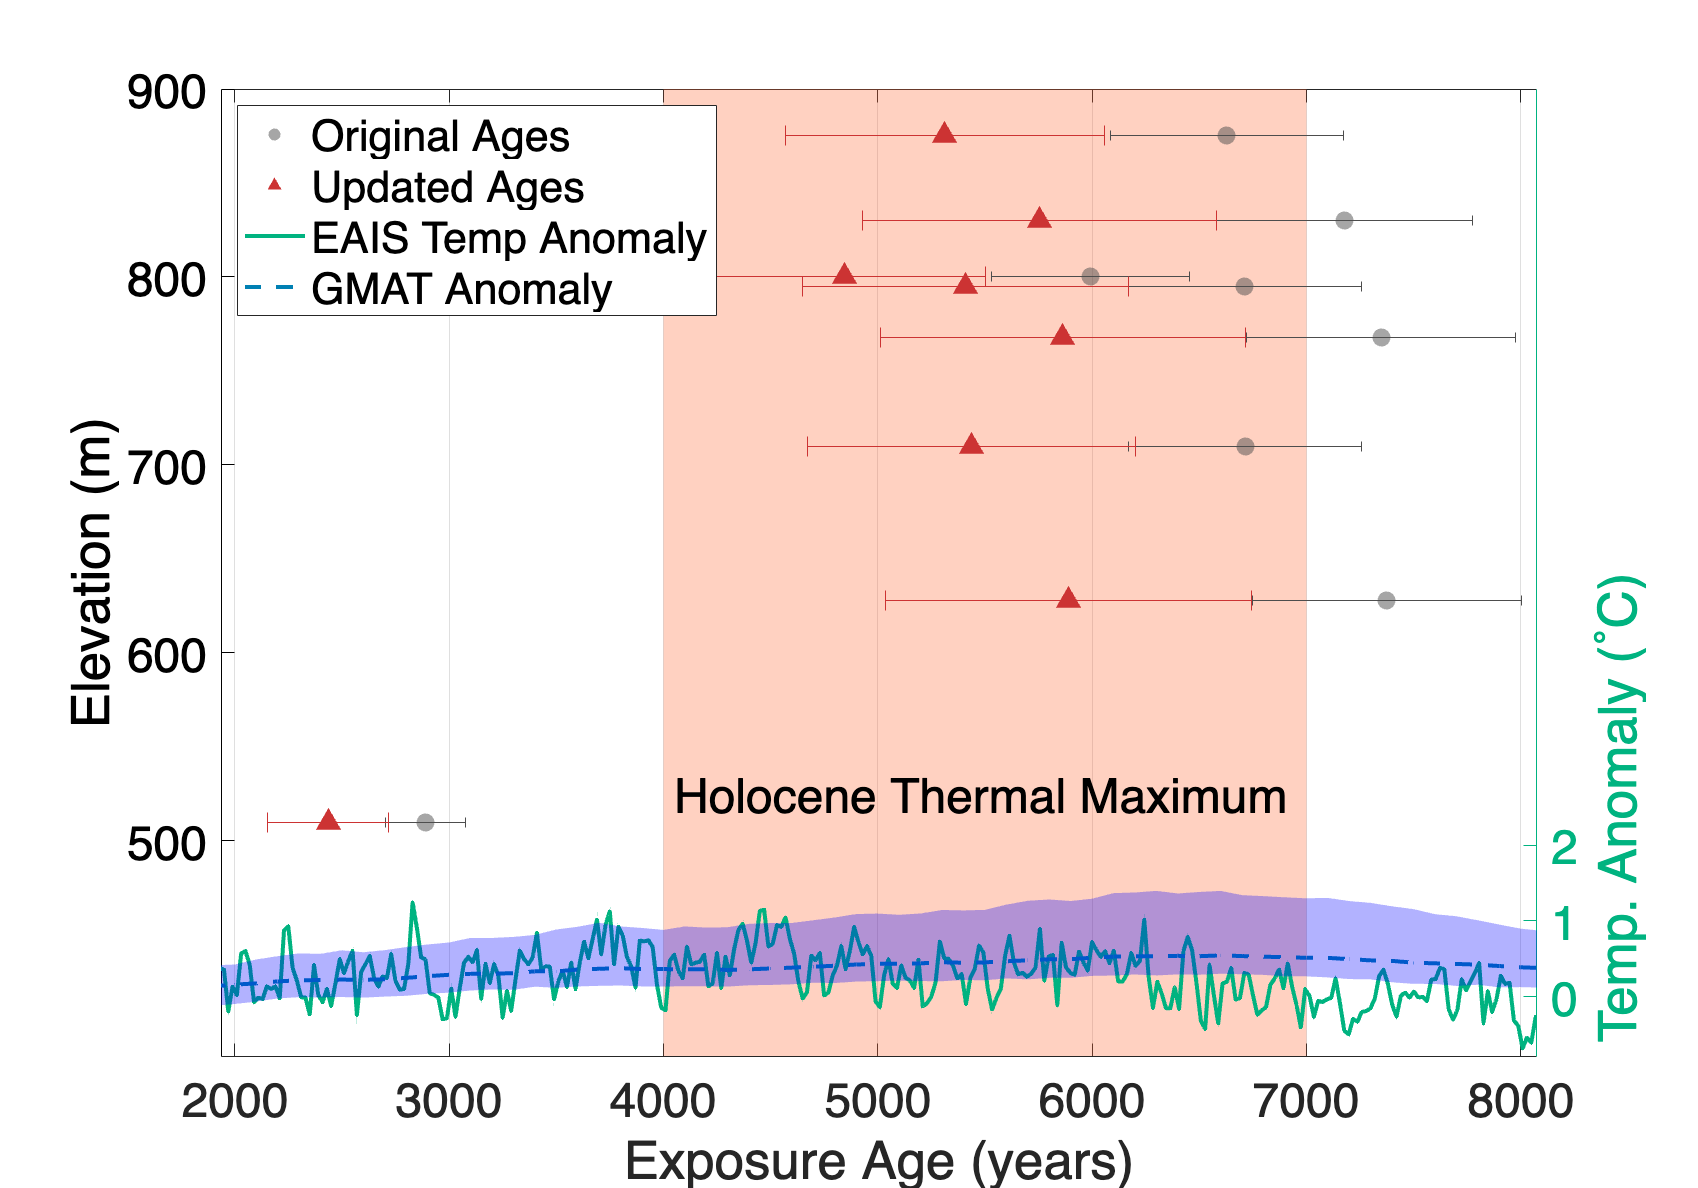

figure;
% --- Background fill ---
hold on;
yyaxis left
fill([4000 7000 7000 4000], [300 300 900 900], [1 0.4 0.2], ...
     'EdgeColor', 'none', 'FaceAlpha', 0.3);  % HCM

% --- Error bars ---
laorig_err = errorbar(las.orig_age, las.elev, las.orig_unc, las.orig_unc, ...
    'horizontal', 'LineStyle', 'none', 'Color', [0.3 0.3 0.3 0.4], ...
    'CapSize', 5);
lanew_err = errorbar(las.calib_age, las.elev, las.calib_unc, las.calib_unc, ...
    'horizontal', 'LineStyle', 'none', 'Color', [0.8 0.2 0.2 0.4], ...
    'CapSize', 10);

% --- Markers ---
laorig = scatter(las.orig_age, las.elev, 80, 'o', ...
    'MarkerEdgeColor', 'none', ...
    'MarkerFaceColor', [0.3 0.3 0.3], ...
    'MarkerFaceAlpha', 0.5, ...
    'MarkerEdgeAlpha', 0.5, ...
    'DisplayName', 'Original Ages');

lanew = scatter(las.calib_age, las.elev, 120, '^', ...
    'MarkerEdgeColor', 'none', ...
    'MarkerFaceColor', [0.8 0.2 0.2], ...
    'MarkerFaceAlpha', 1, ...
    'MarkerEdgeAlpha', 1, ...
    'DisplayName', 'Updated Ages');

plot(data.EATA.age, data.EATA.TA);

% --- Axes and labels ---
xlabel('Exposure Age (years)');
ylabel('Elevation (m)');

grid on;
xlim([min([las.orig_age; las.calib_age]) - 500, ...
      max([las.orig_age; las.calib_age]) + 700]);
ylim([min(las.elev)-125, max(las.elev)+25]);
yticks([500 600 700 800 900])
set(gca, 'FontSize', 24, 'FontName', 'Helvetica', 'Box', 'on', 'YColor', [0 0 0], 'YGrid', 'off');
text(4050, 525, 'Holocene Thermal Maximum', 'FontSize', 24, 'FontName', 'Helvetica')

yyaxis right
hold on
TA = plot(data.EATA.age, data.EATA.TA, 'LineWidth', 2, 'Color', [0 0.7 0.5], 'MarkerFaceColor', 'none', ...
    'MarkerEdgeColor', 'none');
TAmed = plot(data.SurfTemp.age, data.SurfTemp.globalmed, 'LineWidth', 2, 'Color', [0 0.5 0.7], 'MarkerFaceColor', 'none', ...
    'MarkerEdgeColor', 'none');
TAlow = fill([data.SurfTemp.age; flipud(data.SurfTemp.age)], [data.SurfTemp.globallowconf; flipud(data.SurfTemp.globalhighconf)], 'b', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
ylim([-0.8 12])
ylabel('Temp. Anomaly (˚C)', 'HorizontalAlignment','right')
yticks([-1 0 1 2])
set(gca, 'YColor', [0 0.7 0.5]);


TA = legend([laorig, lanew, TA, TAmed], {'Original Ages', 'Updated Ages', 'EAIS Temp Anomaly', 'GMAT Anomaly'}, 'Location', 'northwest');
%title('Lassiter Coast');
set(gcf,'Position',[100 100 1000 700]);
set(gca, 'FontSize', 24, 'FontName', 'Helvetica', 'Box', 'on','YGrid', 'off');


fig = gcf;
%Turn on to save a high-resolution figure
print(fig, 'lassitercoast.png', '-dpng', '-r600')

hold off;

% Calculate residuals
las.residuals = las.calib_age - las.fit_age;
las.residual_unc = las.calib_unc - las.fit_unc;

% Identify positive and negative residuals
pos_idx = las.residuals >= 0;
neg_idx = las.residuals < 0;

% Convert sample names to categorical to ensure bar alignment
cat_names = categorical(las.sample_names);
cat_names = reordercats(cat_names, las.sample_names); % Preserve order

% Create bar chart with different colors
figure;
hold on;

% Plot positive residuals
bar(cat_names(pos_idx), las.residuals(pos_idx), ...
    'FaceColor', [0.2 0.6 0.8], 'EdgeColor', 'k');

% Plot negative residuals
bar(cat_names(neg_idx), las.residuals(neg_idx), ...
    'FaceColor', [0.8 0.3 0.3], 'EdgeColor', 'k');

% Add labels and formatting
xlabel('Sample Name', 'FontSize', 24, 'FontWeight', 'normal', 'FontName', 'Helvetica');
ylabel('Residual (yrs)', 'FontSize', 24, 'FontWeight', 'normal', 'FontName', 'Helvetica');
title('Lassiter Coast Residuals (PR=11.26)','FontSize', 24, 'FontWeight', 'normal', 'FontName', 'Helvetica');

% Set axis properties
set(gca, 'FontSize', 18, 'FontName', 'Helvetica', 'XTickLabelRotation', 45);
ylim([-50 100]);
box on;
clear pos_idx neg_idx cat_names


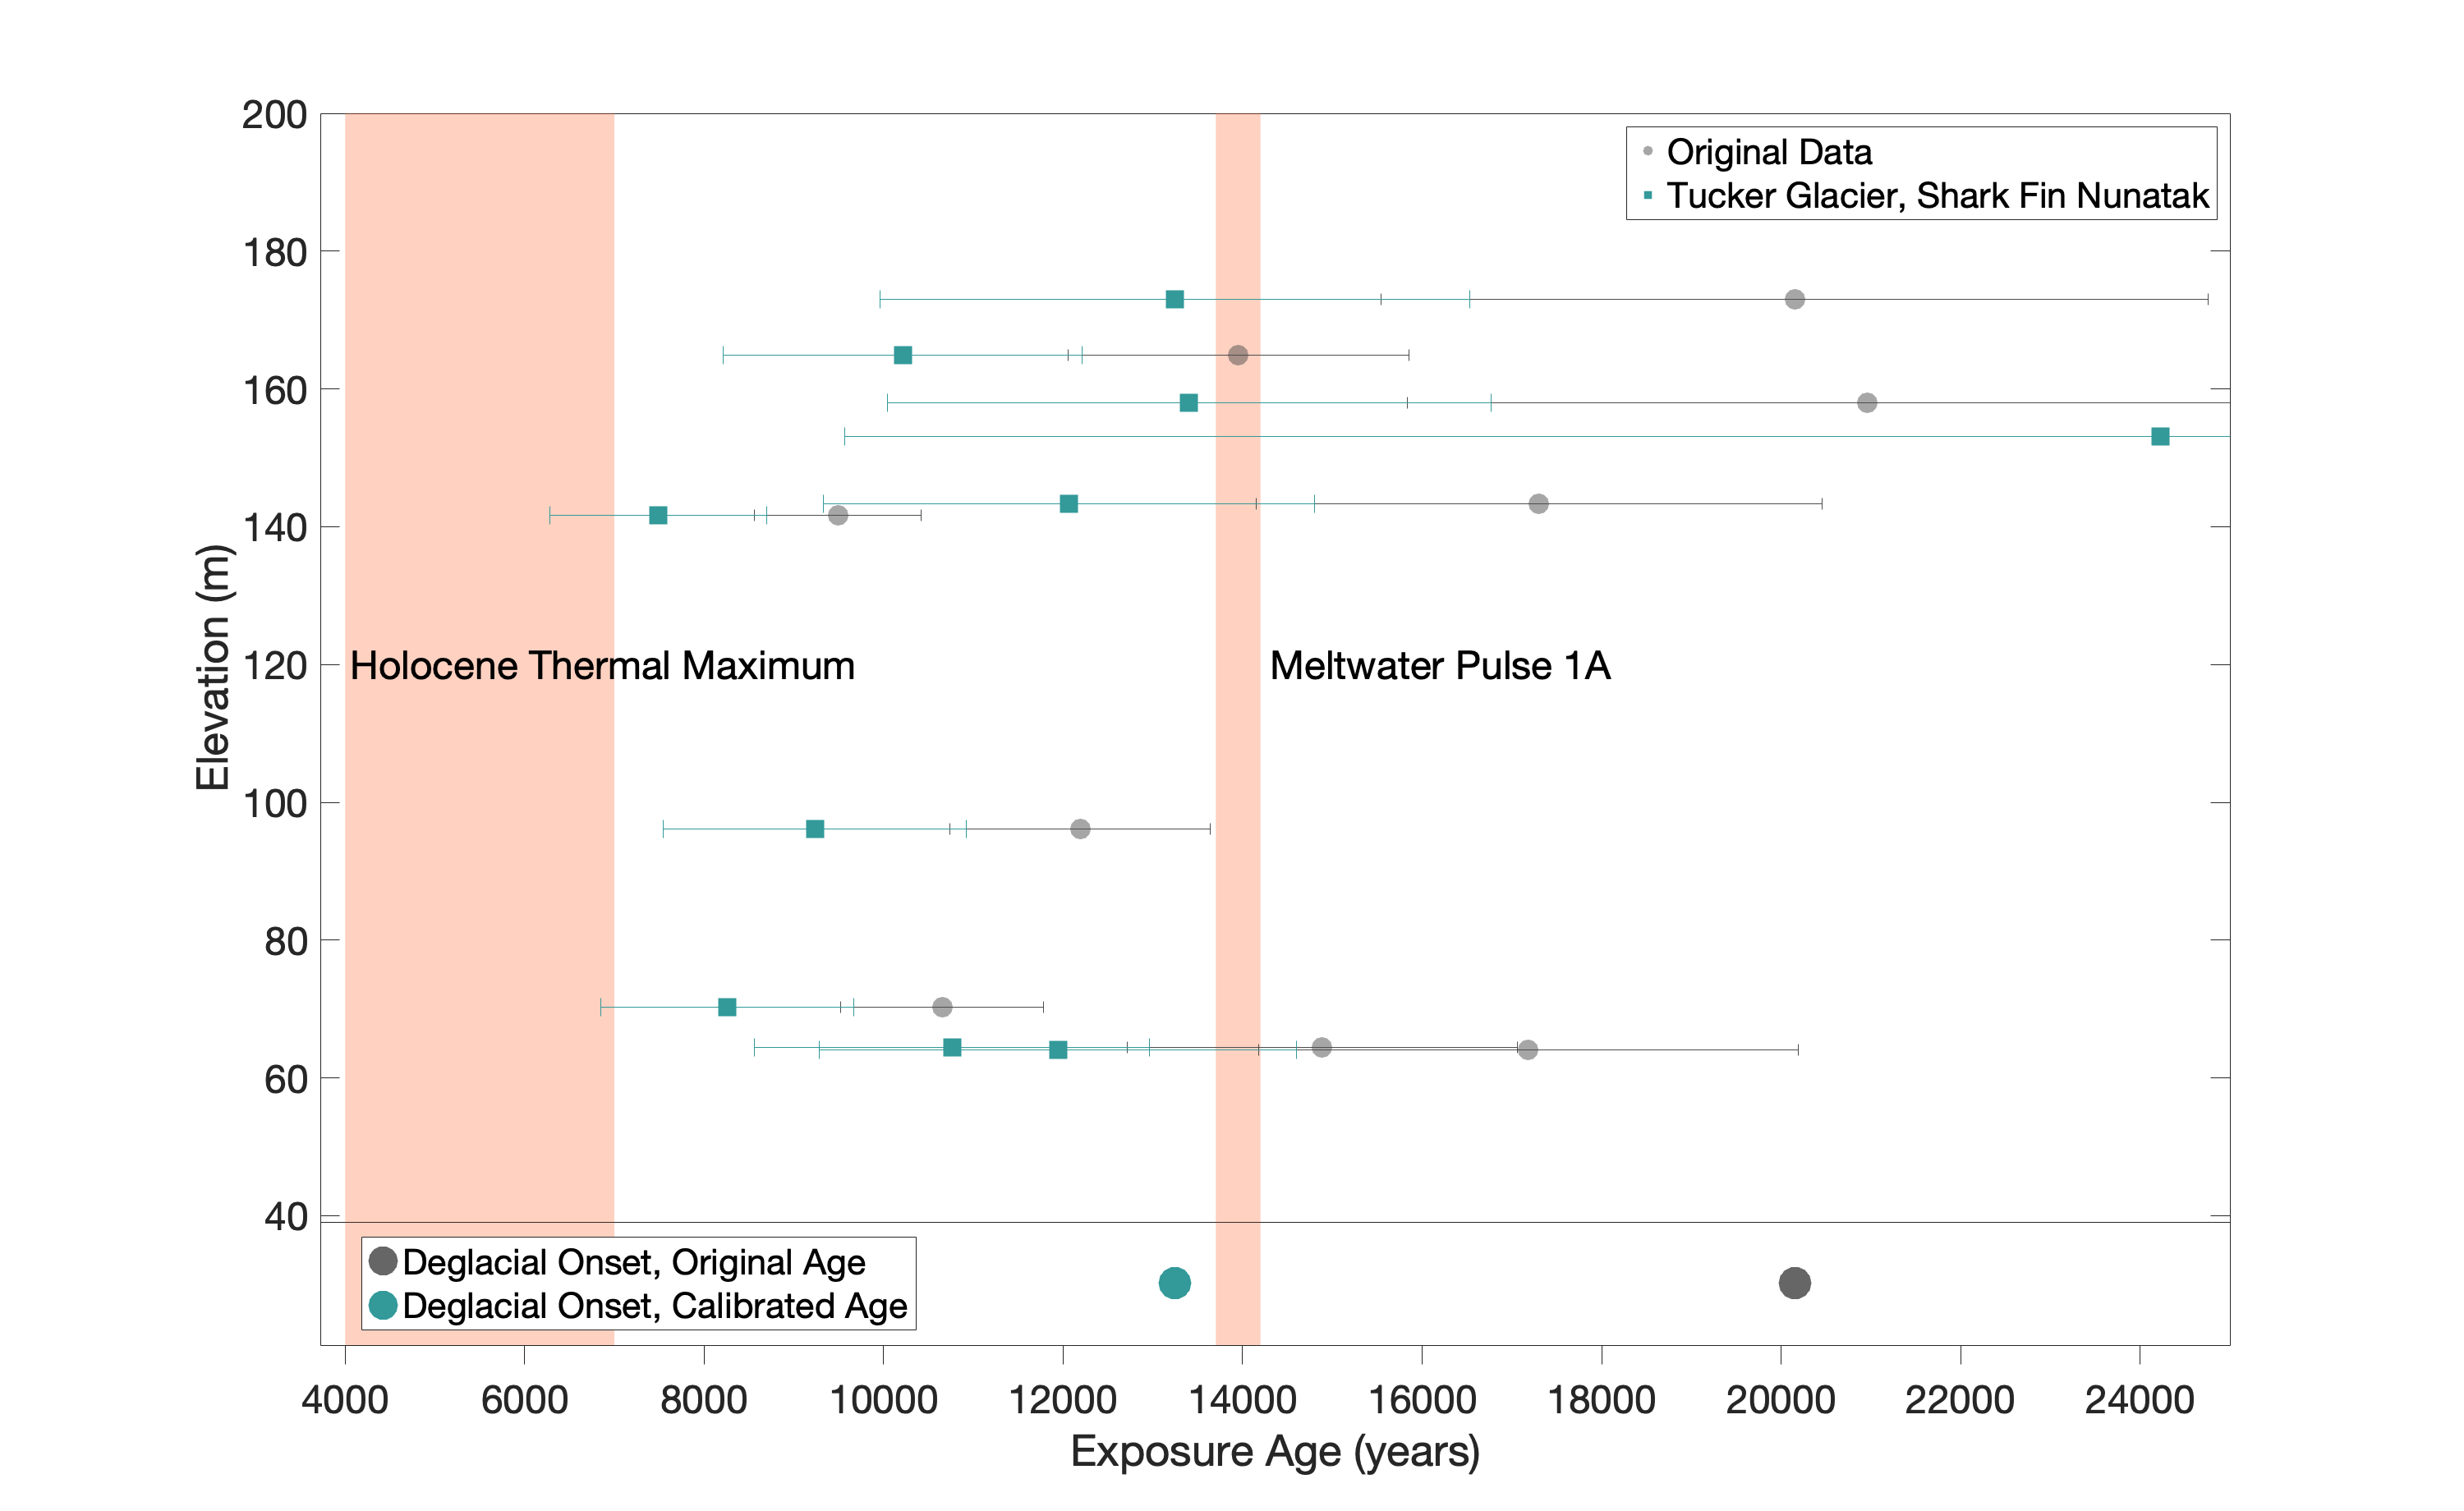

% === Choose which site's MC fit to overlay (1..5) ===
site_id = 5;
N = 5000;           % Monte Carlo iterations

% Always open a fresh, separate figure window each run
set(0,'DefaultFigureVisible','on');
set(0,'DefaultFigureWindowStyle','normal');   % not docked
figure('Color','w'); hold on;

% Shaded intervals (match your 0–600 elevation span ribbons)
fill([4000 7000 7000 4000], [0 0 600 600], [1 0.4 0.2], ...
     'EdgeColor','none','FaceAlpha',0.30);  % HTM
fill([13700 14200 14200 13700], [0 0 600 600], [1 0.4 0.2], ...
     'EdgeColor','none','FaceAlpha',0.30);  % MWP1-A

% --- Site colors (5 sites) ---
colors = [0.2 0.2 0.8;   % 1: Tucker Glacier, Crater Cirque
          0.2 0.6 0.2;   % 2: Tucker Glacier, Skua Basin
          0.8 0.2 0.2;   % 3: Aviator Glacier, Ridge F
          0.6 0.2 0.6;   % 4: Mario Zucchelli Station
          0.2 0.6 0.6];  % 5: Tucker Glacier, Shark Fin Nunatak

% --- Calibrated points by site (ALL sites) ---
for i = 5
    site_idx = (tam.loc == i);

    % --- Original ages with uncertainty (ALL sites, gray cloud) ---
    errorbar(tam.orig_age(site_idx), tam.elev(site_idx), tam.orig_unc(site_idx), tam.orig_unc(site_idx), ...
        'horizontal','LineStyle','none','Color',[0.3 0.3 0.3 0.4],'CapSize',5);

    tamorig = scatter(tam.orig_age(site_idx), tam.elev(site_idx), 160, 'o', ...
        'MarkerEdgeColor','none','MarkerFaceColor',[0.3 0.3 0.3], ...
        'MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5, ...
        'DisplayName','Original Data');

    errorbar(tam.calib_age(site_idx), tam.elev(site_idx), ...
        tam.calib_unc(site_idx), tam.calib_unc(site_idx), ...
        'horizontal','LineStyle','none','Color',[colors(i,:) 0.4], 'CapSize',10);

    newdat(i) = scatter(tam.calib_age(site_idx), tam.elev(site_idx), 200, 's', ...
        'MarkerEdgeColor','none','MarkerFaceColor',colors(i,:), ...
        'MarkerFaceAlpha',1, 'DisplayName', sprintf('Site %d', i));
end

text(4050, 120, 'Holocene Thermal Maximum', 'FontSize', 24, 'FontName', 'Helvetica');
text(14300, 120, 'Meltwater Pulse 1A', 'FontSize', 24, 'FontName', 'Helvetica');


% % ================= Monte Carlo best-fit (CHOSEN site only) =================
m  = (tam.loc == site_id);
% x1 = tam.orig_age(m);   s1 = tam.orig_unc(m);
% x2 = tam.calib_age(m);  s2 = tam.calib_unc(m);
% y  = tam.elev(m);
% 
% % Clean invalids
% v1 = isfinite(x1) & isfinite(s1) & isfinite(y);
% v2 = isfinite(x2) & isfinite(s2) & isfinite(y);
% x1 = x1(v1); s1 = s1(v1); y1 = y(v1);
% x2 = x2(v2); s2 = s2(v2); y2 = y(v2);
% 
% % Guard
% if numel(x1) < 2 || numel(x2) < 2
%     warning('Not enough valid points in site %d for MC regression.', site_id);
% end
% 
% % Run Monte Carlo
% S1 = zeros(N,1); I1 = zeros(N,1);   % original
% S2 = zeros(N,1); I2 = zeros(N,1);   % calibrated
% for n = 1:N
%     x1n = x1 + randn(size(x1)).*s1;
%     x2n = x2 + randn(size(x2)).*s2;
%     p1 = polyfit(x1n, y1, 1);  S1(n)=p1(1); I1(n)=p1(2);
%     p2 = polyfit(x2n, y2, 1);  S2(n)=p2(1); I2(n)=p2(2);
% end
% 
% % Evaluate ensemble on a common grid spanning THIS site's ages
% xmin = min([x1; x2]);  xmax = max([x1; x2]);
% xg   = linspace(xmin-100, xmax+100, 200);
% 
% Y1 = S1.*xg + I1;     % original ensemble
% Y2 = S2.*xg + I2;     % calibrated ensemble
% m1 = mean(Y1,1);  lo1 = prctile(Y1,2.5,1);  hi1 = prctile(Y1,97.5,1);
% m2 = mean(Y2,1);  lo2 = prctile(Y2,2.5,1);  hi2 = prctile(Y2,97.5,1);
% 
% % Overlay MC bands + mean lines (use chosen site's color)
cSite = colors(site_id,:);
% fill([xg fliplr(xg)], [lo2 fliplr(hi2)], cSite, ...
%      'FaceAlpha',0.18, 'EdgeColor','none', 'HandleVisibility','off');
% fill([xg fliplr(xg)], [lo1 fliplr(hi1)], [0.25 0.25 0.25], ...
%      'FaceAlpha',0.15, 'EdgeColor','none', 'HandleVisibility','off');
% 
% % Show mean slopes (optional)
% % text(20000, 310, sprintf('Orig slope: %.2f', mean(S1)));
% % text(20000, 400, sprintf('Calib slope: %.2f', mean(S2)));
% 
% h2 = plot(xg, m2, '-', 'Color', cSite*0.75, 'LineWidth', 2.5, ...
%           'DisplayName', sprintf('Site %d calib fit', site_id));
% h1 = plot(xg, m1, '-', 'Color', [0.15 0.15 0.15], 'LineWidth', 2.5, ...
%           'DisplayName', sprintf('Site %d orig fit', site_id));
% 
% uistack([h1 h2],'top');   % keep lines on top

% ============================ Axes and labels (MAIN) =======================
xlabel('');  % we'll move the x-label to the KDE ribbon
ylabel('Elevation (m)');

grid off;
xlim([min([tam.orig_age; tam.calib_age]) - 500, 25000]);
ylim([min(tam.elev)-25, 200]);
set(gca, 'FontSize', 16, 'FontName', 'Helvetica', 'Box', 'on');
axMain = gca; axMain.XAxis.Exponent = 0;

% ===================== Stacked KDE ribbon for the CHOSEN site ==============
% KDE inputs (chosen site only)
XL = axMain.XLim;                          % support matches panel width
xk = linspace(XL(1), XL(2), 600);          % common grid

% % Bandwidths (Silverman-ish)
% bw1 = 0.9*min(std(x1), iqr(x1)/1.34)*numel(x1)^(-1/5);
% bw2 = 0.9*min(std(x2), iqr(x2)/1.34)*numel(x2)^(-1/5);
% if ~isfinite(bw1) || bw1<=0, bw1 = []; end
% if ~isfinite(bw2) || bw2<=0, bw2 = []; end
% 
% % Kernel densities (each is a SUM of kernels over xk)
% f1 = ksdensity(x1, xk, 'Bandwidth', bw1);   % original (gray)
% f2 = ksdensity(x2, xk, 'Bandwidth', bw2);   % calibrated (site color)
% 
% % Normalize by total so the full stack fills the ribbon
% ftot = f1 + f2;  den = max(ftot);  if den<=0 || ~isfinite(den), den = 1; end
% f1n = f1/den;                 % base (0..f1n)
% f2n = (f1+f2)/den;            % top edge (f1n..f2n)

% Create ribbon axes directly below main (no gap)
posM = axMain.Position;              % [left bottom width height]
hFrac = 0.1;                        % ribbon height fraction
hK   = posM(4) * hFrac;
axK  = axes('Position',[posM(1) posM(2) posM(3) hK], ...
            'Color','none','Box','off','XLim',XL,'YLim',[0 1], ...
            'FontName','Helvetica','FontSize',16);

% Move main axis up to make room (no gap)
axMain.Position = [posM(1) posM(2)+hK posM(3) posM(4)-hK];

% Move x ticks/label to ribbon
axK.XTick = axMain.XTick;     % mirror ticks
axMain.XTick = [];            % hide on main
xlabel(axK,'Exposure Age (years)');
ylim(axK, [0 0.40])

% % Draw stacked areas: original (gray) then calibrated (site color)
hold(axK,'on')
fill(axK, [4000 7000 7000 4000], [0 0 1 1], [1 0.4 0.2], ...
     'EdgeColor','none','FaceAlpha',0.30);  % HTM
fill(axK, [13700 14200 14200 13700], [0 0 1 1 ], [1 0.4 0.2], ...
     'EdgeColor','none','FaceAlpha',0.30);  % MWP1-A
% fill(axK, [xk fliplr(xk)], [zeros(size(xk)) fliplr(f1n)], ...
%      [0.40 0.40 0.40], 'EdgeColor','none', 'FaceAlpha',0.28, 'HandleVisibility','off');
% fill(axK, [xk fliplr(xk)], [f1n fliplr(f2n)], ...
%      cSite, 'EdgeColor','none', 'FaceAlpha',0.28, 'HandleVisibility','off');
% l1= xline(axK, mean(tam.orig_age(m)), 'LineWidth',2, 'Color', [0.4 0.4 0.4], 'DisplayName', 'Original Age Mean');
% l2 = xline(axK, mean(tam.calib_age(m)), 'LineWidth',2, 'Color', cSite, 'DisplayName', 'Calibrated Age Mean');
%od1 = plot(max(tam.orig_age(m)), 0.20, 'Marker', 'o', 'MarkerSize', 20, 'MarkerEdgeColor', 'none', 'MarkerFaceColor', [0.4 0.4 0.4], 'LineStyle','none', 'DisplayName','Deglacial Onset, Original Age');
%od2 = plot(max(tam.calib_age(m)), 0.20, 'Marker', 'o', 'MarkerSize', 20, 'MarkerEdgeColor', 'none', 'MarkerFaceColor', cSite, 'LineStyle','none', 'DisplayName','Deglacial Onset, Calibrated Age');
od1 = plot(20153, 0.20, 'Marker', 'o', 'MarkerSize', 20, 'MarkerEdgeColor', 'none', 'MarkerFaceColor', [0.4 0.4 0.4], 'LineStyle','none', 'DisplayName','Deglacial Onset, Original Age');
od2 = plot(13247, 0.20, 'Marker', 'o', 'MarkerSize', 20, 'MarkerEdgeColor', 'none', 'MarkerFaceColor', cSite, 'LineStyle','none', 'DisplayName','Deglacial Onset, Calibrated Age');


legend([od1, od2], 'Location', 'best');

% Clean ribbon axis
axK.YTick = []; axK.TickDir = 'out'; axK.Layer = 'top';
axK.XTick = [4000 6000 8000 10000 12000 14000 16000 18000 20000 22000 24000];
axK.XAxis.Exponent = 0;
% ylabel('Probability')

% Keep x-axes synced for pan/zoom
linkaxes([axMain axK],'x');
axes(axMain);  % back to main axes
% ==========================================================================

hold off
legend([tamorig, newdat(5)], ...% newdat(2), newdat(3), newdat(4), newdat(5)], ...
       {'Original Data', ...
        %'Tucker Glacier, Crater Cirque'});%, ...
        %'Tucker Glacier, Skua Basin'});%, ...
         %'Aviator Glacier, Ridge F'});%, ...
        % 'Mario Zucchelli Station', ...
        'Tucker Glacier, Shark Fin Nunatak'});

set(gcf,'Position',[100 100 1500 1000]);
set(gca, 'FontSize', 24, 'FontName', 'Helvetica', 'Box', 'on','YGrid', 'off');
set(axK, 'FontSize', 24, 'FontName', 'Helvetica', 'Box', 'on','YGrid', 'off');

fig = gcf;
%Turn on to save a high-resolution figure
%print(fig, 'tamSFN.png', '-dpng', '-r600')

% Perform random draws of the data to determine the best fit range for the
% kay peak data

% Subset
kp_bin = [3 19 17 4 22 14];
x1 = ase.orig_age(kp_bin);
y  = ase.elev(kp_bin);
x2 = ase.calib_age(kp_bin);
x1_err = ase.orig_unc(kp_bin);
x2_err = ase.calib_unc(kp_bin);


% ---- Monte Carlo linear fit for Kay Peak subset ----
N = 5000;

s1 = zeros(N,1); i1 = zeros(N,1);
s2 = zeros(N,1); i2 = zeros(N,1);

for n = 1:N
    x1n = x1 + randn(size(x1)).*x1_err;   % original ages w/ noise
    x2n = x2 + randn(size(x2)).*x2_err;   % calibrated ages w/ noise

    p1 = polyfit(x1n, y, 1);
    p2 = polyfit(x2n, y, 1);

    s1(n) = p1(1);  i1(n) = p1(2);
    s2(n) = p2(1);  i2(n) = p2(2);
end

% Evaluate fits on a common grid
xgrid = linspace(min([x1; x2])-100, 9000, 200);
Y1 = s1.*xgrid + i1;     % all MC lines (original)
Y2 = s2.*xgrid + i2;     % all MC lines (calibrated)

% Mean + 95 % envelope
m1 = mean(Y1,1);
lo1 = prctile(Y1,2.5,1); hi1 = prctile(Y1,97.5,1);

m2 = mean(Y2,1);
lo2 = prctile(Y2,2.5,1); hi2 = prctile(Y2,97.5,1);





figure;
hold on;

fill([4000 7000 7000 4000], [100 100 1000 1000], [1 0.4 0.2], ...
     'EdgeColor', 'none', 'FaceAlpha', 0.1);  % HTM

fill([13700 14200 14200 13700], [100 100 1000 1000], [1 0.4 0.2], ...
     'EdgeColor', 'none', 'FaceAlpha', 0.1);  % MWP1-A

% Original ages with uncertainty
errorbar(ase.orig_age, ase.elev, ase.orig_unc, ase.orig_unc, 'horizontal', 'LineStyle', ...
    'none', 'Color', [0.3 0.3 0.3 0.4], ...
    'CapSize', 5);

% --- Markers ---
asorig = scatter(ase.orig_age, ase.elev, 80, 'o', ...
    'MarkerEdgeColor', 'none', ...
    'MarkerFaceColor', [0.3 0.3 0.3], ...
    'MarkerFaceAlpha', 0.5, ...
    'MarkerEdgeAlpha', 0.5, ...
    'DisplayName', 'Original Ages');


colors = [0.2 0.2 0.8;
          0.2 0.6 0.2;
          0.8 0.2 0.2;
          0.6 0.2 0.6];

% Loop over 4 sites
for i = 1:4
    site_idx = (ase.loc == i);  % logical index for each site

    % --- Error bars for each site ---
    errorbar(ase.calib_age(site_idx), ase.elev(site_idx), ...
        ase.calib_unc(site_idx), ase.calib_unc(site_idx), ...
        'horizontal', 'LineStyle', 'none', ...
        'Color', [colors(i,:) 0.4], 'CapSize', 10);

    % --- Scatter points ---
    newdat(i) = scatter(ase.calib_age(site_idx), ase.elev(site_idx), 120, 's', ...
        'MarkerEdgeColor', 'none', ...
        'MarkerFaceColor', colors(i,:), ...
        'MarkerFaceAlpha', 1, ...
        'DisplayName', sprintf('Site %d', i));
end

% ---- Add Kay Peak best-fit lines + 95 % bands to current axes ----
hold on

% calibrated (green)
fill([xgrid fliplr(xgrid)], [lo2 fliplr(hi2)], [0.2 0.6 0.2], ...
     'FaceAlpha',0.18, 'EdgeColor','none', 'HandleVisibility','off');
h2 = plot(xgrid, m2, '-', 'Color',[0.2 0.6 0.2], ...
          'LineWidth',2, 'DisplayName','Kay Peak (calib fit)');

% Compute slope stats
slope_mean = mean(s2);
slope_lo = prctile(s2, 2.5);
slope_hi = prctile(s2, 97.5);

% Add text to plot (adjust position as needed)
text(9100, 450, sprintf('Slope: %.4f ± %.4f', slope_mean, (slope_hi - slope_lo)/2), ...
     'FontSize', 20, 'FontName', 'Helvetica', 'Color', [0.2 0.6 0.2]);

% original (dark gray)
fill([xgrid fliplr(xgrid)], [lo1 fliplr(hi1)], [0.15 0.15 0.15], ...
     'FaceAlpha',0.15, 'EdgeColor','none', 'HandleVisibility','off');
h1 = plot(xgrid, m1, '-', 'Color',[0.15 0.15 0.15], ...
          'LineWidth',2, 'DisplayName','Kay Peak (orig fit)');

% Compute slope stats
slope_mean2 = mean(s1);
slope_lo2 = prctile(s1, 2.5);
slope_hi2 = prctile(s1, 97.5);

% Add text to plot (adjust position as needed)
text(9100, 400, sprintf('Slope: %.4f ± %.4f', slope_mean2, (slope_hi2 - slope_lo2)/2), ...
     'FontSize', 20, 'FontName', 'Helvetica', 'Color', [0.15 0.15 0.15]);
text(3500, 700, 'Holocene Themal Maximum', 'FontSize', 20, 'FontName', 'Helvetica');
text(12500, 700, 'Meltwater Pulse 1A', 'FontSize', 20, 'FontName', 'Helvetica');


% optional: keep on top of scatter/errorbars
uistack([h1 h2],'bottom');


% Axis and labels
xlabel('Exposure Age (years)');
ylabel('Elevation (m)');
%title('Pope Glacier and Bear Penninsula');

% Formatting
grid on;
%legend('Location', 'best');
xlim([min([ase.orig_age; ase.calib_age]) - 500, max([ase.orig_age; ase.calib_age]) + 700]);
ylim([min(ase.elev)-25, max(ase.elev)+25]);
set(gca, 'FontSize', 20, 'FontName', 'Helvetica', 'Box', 'on', 'YGrid', 'off');
ax = gca;
ax.XAxis.Exponent = 0;
hold off
legend([asorig newdat(1) newdat(2) newdat(3) newdat(4)], {'Original Data', 'Bear Penninsula', 'Kay Peak', 'Notebook Cliffs', 'Turtle Rock'});
set(gcf,'Position',[100 100 1500 1000]);
fig = gcf;
%Turn on to save a high-resolution figure
%print(fig, 'aseslopecompare.png', '-dpng', '-r600')

% Always open a fresh, separate figure window each run
set(0,'DefaultFigureVisible','on');
set(0,'DefaultFigureWindowStyle','normal');   % not docked
figure('Color','w'); hold on;

% --- Shaded intervals ---
fill([4000 7000 7000 4000], [100 100 1000 1000], [1 0.4 0.2], ...
     'EdgeColor','none','FaceAlpha',0.10);  % HTM
fill([13700 14200 14200 13700], [100 100 1000 1000], [1 0.4 0.2], ...
     'EdgeColor','none','FaceAlpha',0.10);  % MWP1-A

% --- Original ages with uncertainty (gray) ---
errorbar(ase.orig_age, ase.elev, ase.orig_unc, ase.orig_unc, ...
    'horizontal','LineStyle','none','Color',[0.3 0.3 0.3 0.4],'CapSize',5);

asorig = scatter(ase.orig_age, ase.elev, 80, 'o', ...
    'MarkerEdgeColor','none','MarkerFaceColor',[0.3 0.3 0.3], ...
    'MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5, ...
    'DisplayName','Original Data');

% --- Site colors ---
colors = [0.2 0.2 0.8;   % Bear Peninsula
          0.2 0.6 0.2;   % Kay Peak
          0.8 0.2 0.2;   % Notebook Cliffs
          0.6 0.2 0.6];  % Turtle Rock

% --- Calibrated points by site ---
for i = 1:4
    site_idx = (ase.loc == i);
        errorbar(ase.calib_age(site_idx), ase.elev(site_idx), ...
            ase.calib_unc(site_idx), ase.calib_unc(site_idx), ...
            'horizontal','LineStyle','none','Color',[colors(i,:) 0.4], 'CapSize',10);
    
        newdat(i) = scatter(ase.calib_age(site_idx), ase.elev(site_idx), 120, 's', ...
            'MarkerEdgeColor','none','MarkerFaceColor',colors(i,:), ...
            'MarkerFaceAlpha',1, 'DisplayName',sprintf('Site %d', i));
end

% Main Plot Formatting
ylabel('Elevation (m)');
grid on;
xlim([min([ase.orig_age; ase.calib_age]) - 500, max([ase.orig_age; ase.calib_age]) + 700]);
ylim([min(ase.elev)-25, max(ase.elev)+25]);
set(gca,'FontSize',20,'FontName','Helvetica','Box','on','YGrid','off');
axMain = gca; axMain.XAxis.Exponent = 0; axMain.XGrid = 'on';
text(axMain, 3500, 700, 'Holocene Thermal Maximum', 'FontSize', 20, 'FontName', 'Helvetica');
text(axMain, 12500, 700, 'Meltwater Pulse 1A', 'FontSize', 20, 'FontName', 'Helvetica');

% Bottom Ribbon
% Data (Kay Peak only)
kp     = (ase.loc == 2 & ase.elev<200 & ase.orig_age<10000);
x_orig = ase.orig_age(kp);  x_orig = x_orig(isfinite(x_orig));
x_cal  = ase.calib_age(kp); x_cal  = x_cal(isfinite(x_cal));

% Common x-grid across current x-range
XL  = axMain.XLim;
xk  = linspace(XL(1), XL(2), 600);

% Bandwidths (Silverman-ish)
bw1 = 0.9*min(std(x_orig), iqr(x_orig)/1.34)*numel(x_orig)^(-1/5);
bw2 = 0.9*min(std(x_cal),  iqr(x_cal)/1.34)*numel(x_cal)^(-1/5);
if ~isfinite(bw1) || bw1<=0, bw1 = []; end
if ~isfinite(bw2) || bw2<=0, bw2 = []; end

% KDEs evaluated on the same grid (each is a SUM of kernels)
f1 = ksdensity(x_orig, xk, 'Bandwidth', bw1);   % original
f2 = ksdensity(x_cal,  xk, 'Bandwidth', bw2);   % calibrated

% Normalize by the max of the TOTAL so the full stack fills the ribbon
ftot = f1 + f2;  den = max(ftot);  if den<=0 || ~isfinite(den), den = 1; end
f1n  = f1 / den;                     % base (gray)
f2n  = (f1 + f2) / den;              % top edge of stack (gray+green)

% Create a dedicated ribbon axes directly below (zero gap)
posM = axMain.Position;              % [left bottom width height]
hFrac = 0.18;                        % ribbon height as fraction of main
hK   = posM(4) * hFrac;              % ribbon height (in normalized units)
axK  = axes('Position',[posM(1) posM(2) posM(3) hK], ...
            'Color','none','Box','off','XLim',XL,'YLim',[0 1], ...
            'FontName','Helvetica','FontSize',20);
axMain.Position = [posM(1) posM(2)+hK posM(3) posM(4)-hK];  % no gap

% Move ticks/label to the ribbon
axK.XTick = axMain.XTick;            % mirror main ticks
axMain.XTick = [];                   % remove from main
xlabel(axK,'Exposure Age (years)');
ylabel(axK, 'Probability');

hold(axK,'on')
fill(axK, [xk fliplr(xk)], [zeros(size(xk)) fliplr(f1n)], ...
     [0.40 0.40 0.40], 'EdgeColor','none', 'FaceAlpha',0.28, 'HandleVisibility','off');
fill(axK, [xk fliplr(xk)], [f1n fliplr(f2n)], ...
     [0.20 0.60 0.20], 'EdgeColor','none', 'FaceAlpha',0.28, 'HandleVisibility','off');
xline(axK, mean(x_orig), 'Color', [0.45 0.45 0.45 1], 'LineWidth', 2);
xline(axK, mean(x_cal), 'Color', [0.20 0.60 0.20 1], 'LineWidth', 2);
text(axK, 6400, 0.9, sprintf('Mean Age: %0.0f', mean(x_orig)), 'FontSize', 20, 'FontName', 'Helvetica', 'Color', [0.15 0.15 0.15])
text(axK, 2100, 0.95, sprintf('Mean Age: %0.0f', mean(x_cal)), 'FontSize', 20, 'FontName', 'Helvetica', 'Color', [0.20 0.60 0.20])



% Clean ribbon axis (only x ticks/label shown)
axK.YTick = []; axK.TickDir = 'out'; axK.Layer = 'top';
ylim(axK, [0 max(f2n)+0.05])

% Keep x-axes synced
linkaxes([axMain axK],'x');
axes(axMain);  % return focus to main axes
% ============================================================================

% --- Final touches ---
set(gcf,'Position',[100 100 1500 1000]);
axK.XAxis.Exponent = 0;
axK.XTick = [4000 6000 8000 10000 12000 14000 16000 18000 20000];
grid on;
set(axMain, 'XGrid', 'on', 'YGrid', 'off')
legend([asorig newdat(1) newdat(2) newdat(3) newdat(4)], ...
       {'Original Data','Bear Penninsula','Kay Peak','Notebook Cliffs','Turtle Rock'});

fig = gcf;
%Turn on to save a high-resolution figure
print(fig, 'aselowerkpcompare.png', '-dpng', '-r600')

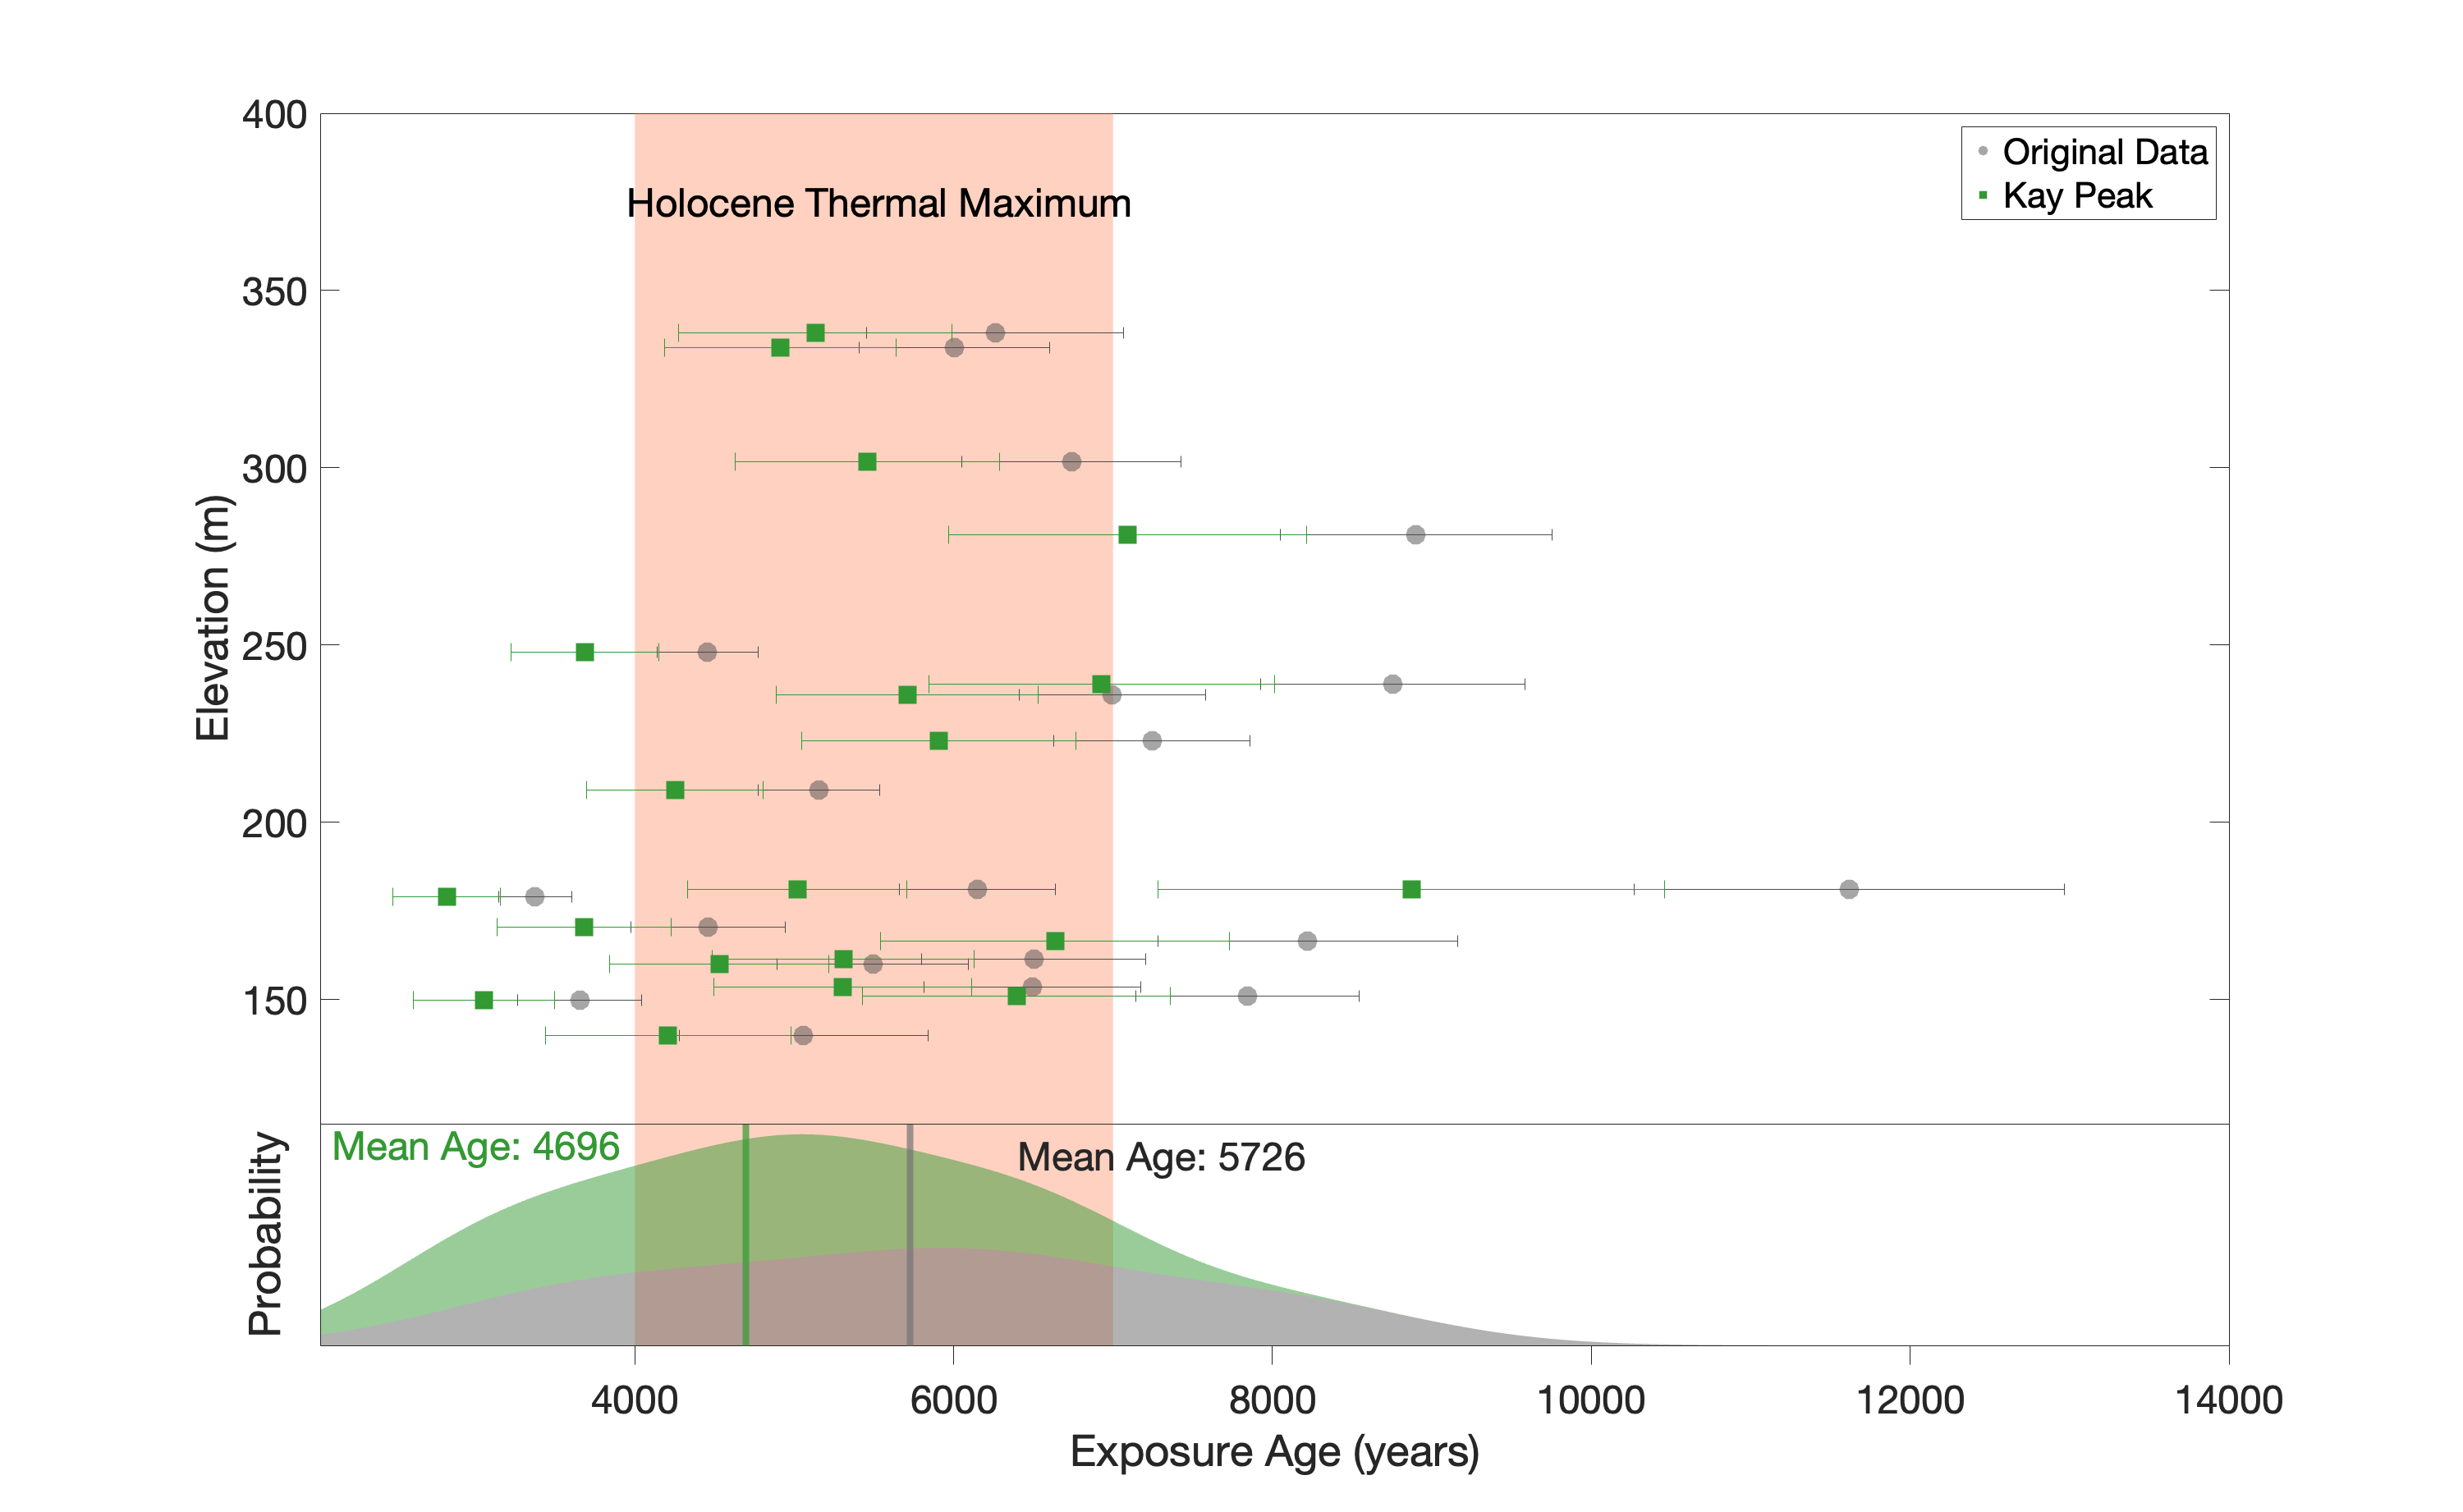

% Always open a fresh, separate figure window each run
set(0,'DefaultFigureVisible','on');
set(0,'DefaultFigureWindowStyle','normal');   % not docked
figure('Color','w'); hold on;

% --- Shaded intervals ---
fill([4000 7000 7000 4000], [100 100 1000 1000], [1 0.4 0.2], ...
     'EdgeColor','none','FaceAlpha',0.30);  % HTM


% --- Site colors ---
colors = [0.2 0.2 0.8;   % Bear Peninsula
          0.2 0.6 0.2;   % Kay Peak
          0.8 0.2 0.2;   % Notebook Cliffs
          0.6 0.2 0.6];  % Turtle Rock

% --- Calibrated points by site ---
for i = 2
    site_idx = (ase.loc == i);

            % --- Original ages with uncertainty (gray) ---
        errorbar(ase.orig_age(site_idx), ase.elev(site_idx), ase.orig_unc(site_idx), ase.orig_unc(site_idx), ...
            'horizontal','LineStyle','none','Color',[0.3 0.3 0.3 0.4],'CapSize',5);

        asorig = scatter(ase.orig_age(site_idx), ase.elev(site_idx), 150, 'o', ...
            'MarkerEdgeColor','none','MarkerFaceColor',[0.3 0.3 0.3], ...
            'MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5, ...
            'DisplayName','Original Data');

        errorbar(ase.calib_age(site_idx), ase.elev(site_idx), ...
            ase.calib_unc(site_idx), ase.calib_unc(site_idx), ...
            'horizontal','LineStyle','none','Color',[colors(i,:) 0.4], 'CapSize',10);
    
        newdat(i) = scatter(ase.calib_age(site_idx), ase.elev(site_idx), 200, 's', ...
            'MarkerEdgeColor','none','MarkerFaceColor',colors(i,:), ...
            'MarkerFaceAlpha',1, 'DisplayName',sprintf('Site %d', i));

end

% Main Plot Formatting
ylabel('Elevation (m)');
grid on;
xlim([min([ase.orig_age; ase.calib_age]) - 500, 14000]);
ylim([min(ase.elev)-25, 400]);
set(gca,'FontSize',20,'FontName','Helvetica','Box','on','YGrid','off');
axMain = gca; axMain.XAxis.Exponent = 0; axMain.XGrid = 'on';
text(axMain, 3950, 375, 'Holocene Thermal Maximum', 'FontSize', 24, 'FontName', 'Helvetica');

% Bottom Ribbon
% Data (Kay Peak only)
kp     = (ase.loc == 2 & ase.elev<200 & ase.orig_age<10000);
x_orig = ase.orig_age(kp);  x_orig = x_orig(isfinite(x_orig));
x_cal  = ase.calib_age(kp); x_cal  = x_cal(isfinite(x_cal));

% Common x-grid across current x-range
XL  = axMain.XLim;
xk  = linspace(XL(1), XL(2), 600);

% Bandwidths (Silverman-ish)
bw1 = 0.9*min(std(x_orig), iqr(x_orig)/1.34)*numel(x_orig)^(-1/5);
bw2 = 0.9*min(std(x_cal),  iqr(x_cal)/1.34)*numel(x_cal)^(-1/5);
if ~isfinite(bw1) || bw1<=0, bw1 = []; end
if ~isfinite(bw2) || bw2<=0, bw2 = []; end

% KDEs evaluated on the same grid (each is a SUM of kernels)
f1 = ksdensity(x_orig, xk, 'Bandwidth', bw1);   % original
f2 = ksdensity(x_cal,  xk, 'Bandwidth', bw2);   % calibrated

% Normalize by the max of the TOTAL so the full stack fills the ribbon
ftot = f1 + f2;  den = max(ftot);  if den<=0 || ~isfinite(den), den = 1; end
f1n  = f1 / den;                     % base (gray)
f2n  = (f1 + f2) / den;              % top edge of stack (gray+green)

% Create a dedicated ribbon axes directly below (zero gap)
posM = axMain.Position;              % [left bottom width height]
hFrac = 0.18;                        % ribbon height as fraction of main
hK   = posM(4) * hFrac;              % ribbon height (in normalized units)
axK  = axes('Position',[posM(1) posM(2) posM(3) hK], ...
            'Color','none','Box','off','XLim',XL,'YLim',[0 1], ...
            'FontName','Helvetica','FontSize',20);
axMain.Position = [posM(1) posM(2)+hK posM(3) posM(4)-hK];  % no gap

% Move ticks/label to the ribbon
axK.XTick = axMain.XTick;            % mirror main ticks
axMain.XTick = [];                   % remove from main
xlabel(axK,'Exposure Age (years)');
ylabel(axK, 'Probability');

hold(axK,'on')
fill(axK, [4000 7000 7000 4000], [0 0 1.2 1.2], [1 0.4 0.2], ...
     'EdgeColor','none','FaceAlpha',0.30);  % HTM
fill(axK, [xk fliplr(xk)], [zeros(size(xk)) fliplr(f1n)], ...
     [0.40 0.40 0.40], 'EdgeColor','none', 'FaceAlpha',0.5, 'HandleVisibility','off');
fill(axK, [xk fliplr(xk)], [f1n fliplr(f2n)], ...
     [0.20 0.60 0.20], 'EdgeColor','none', 'FaceAlpha',0.5, 'HandleVisibility','off');
xline(axK, mean(x_orig), 'Color', [0.45 0.45 0.45 1], 'LineWidth', 4);
xline(axK, mean(x_cal), 'Color', [0.20 0.60 0.20 1], 'LineWidth', 4);
text(axK, 6400, 0.9, sprintf('Mean Age: %0.0f', mean(x_orig)), 'FontSize', 24, 'FontName', 'Helvetica', 'Color', [0.15 0.15 0.15])
text(axK, 2100, 0.95, sprintf('Mean Age: %0.0f', mean(x_cal)), 'FontSize', 24, 'FontName', 'Helvetica', 'Color', [0.20 0.60 0.20])



% Clean ribbon axis (only x ticks/label shown)
axK.YTick = []; axK.TickDir = 'out'; axK.Layer = 'top';
ylim(axK, [0 max(f2n)+0.05])

% Keep x-axes synced
linkaxes([axMain axK],'x');
axes(axMain);  % return focus to main axes
% ============================================================================

% --- Final touches ---
set(gcf,'Position',[100 100 1500 1000]);
axK.XAxis.Exponent = 0;
axK.XTick = [4000 6000 8000 10000 12000 14000];
grid on;
set(axMain, 'XGrid', 'on', 'YGrid', 'off')
set(axMain, 'FontSize', 24, 'FontName', 'Helvetica', 'Box', 'on','YGrid', 'off');
set(axK, 'FontSize', 24, 'FontName', 'Helvetica', 'Box', 'on','YGrid', 'off');
legend([asorig newdat(2)], ...
       {'Original Data', 'Kay Peak'}); %, 'Bear Penninsula', 'Notebook Cliffs','Turtle Rock'});


fig = gcf;
%Turn on to save a high-resolution figure
%print(fig, 'aselowerkpcompare.png', '-dpng', '-r600')

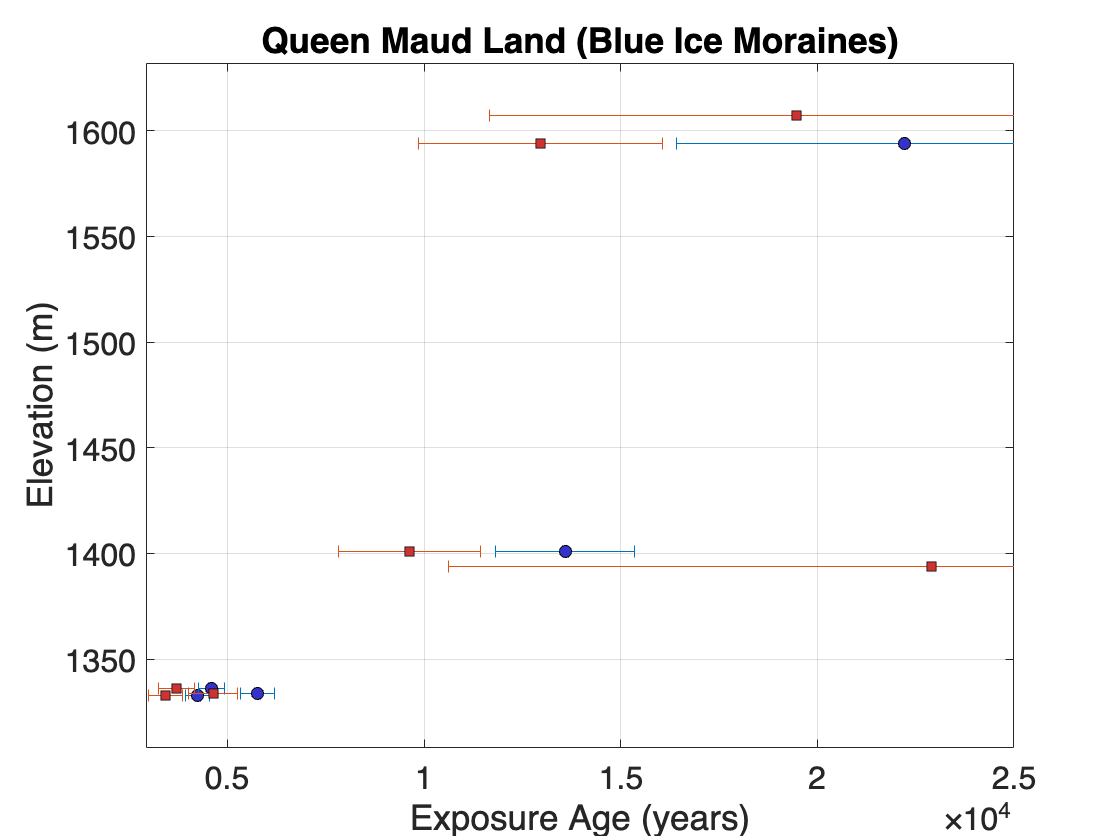



figure;
% Background fill regions
%fill([6000 8000 8000 6000], [400 400 900 900], [0.2 0.4 1], ...
%     'EdgeColor', 'none', 'FaceAlpha', 0.2);  % blue zone
hold on;
%fill([4000 6000 6000 4000], [400 400 900 900], [0 0 0], ...
%     'EdgeColor', 'none', 'FaceAlpha', 0.1);  % gray zone

% Original ages with uncertainty
errorbar(dml.orig_age, dml.elev, dml.orig_unc, dml.orig_unc, 'o', ...
    'horizontal', 'LineStyle', 'none', ...
    'MarkerFaceColor', [0.2 0.2 0.8], 'MarkerEdgeColor', 'k', ...
    'DisplayName', 'Original Age');

% New ages with uncertainty
errorbar(dml.calib_age, dml.elev, dml.calib_unc, dml.calib_unc, 's', ...
    'horizontal', 'LineStyle', 'none', ...
    'MarkerFaceColor', [0.8 0.2 0.2], 'MarkerEdgeColor', 'k', ...
    'DisplayName', 'New Age');

% Axis and labels
xlabel('Exposure Age (years)');
ylabel('Elevation (m)');
title('Queen Maud Land (Blue Ice Moraines)');

% Formatting
grid on;
%legend('Location', 'best');
xlim([min([dml.orig_age; dml.calib_age]) - 500, 25000]);
ylim([min(dml.elev)-25, max(dml.elev)+25]);
set(gca, 'FontSize', 16, 'FontName', 'Helvetica', 'Box', 'on');
hold off

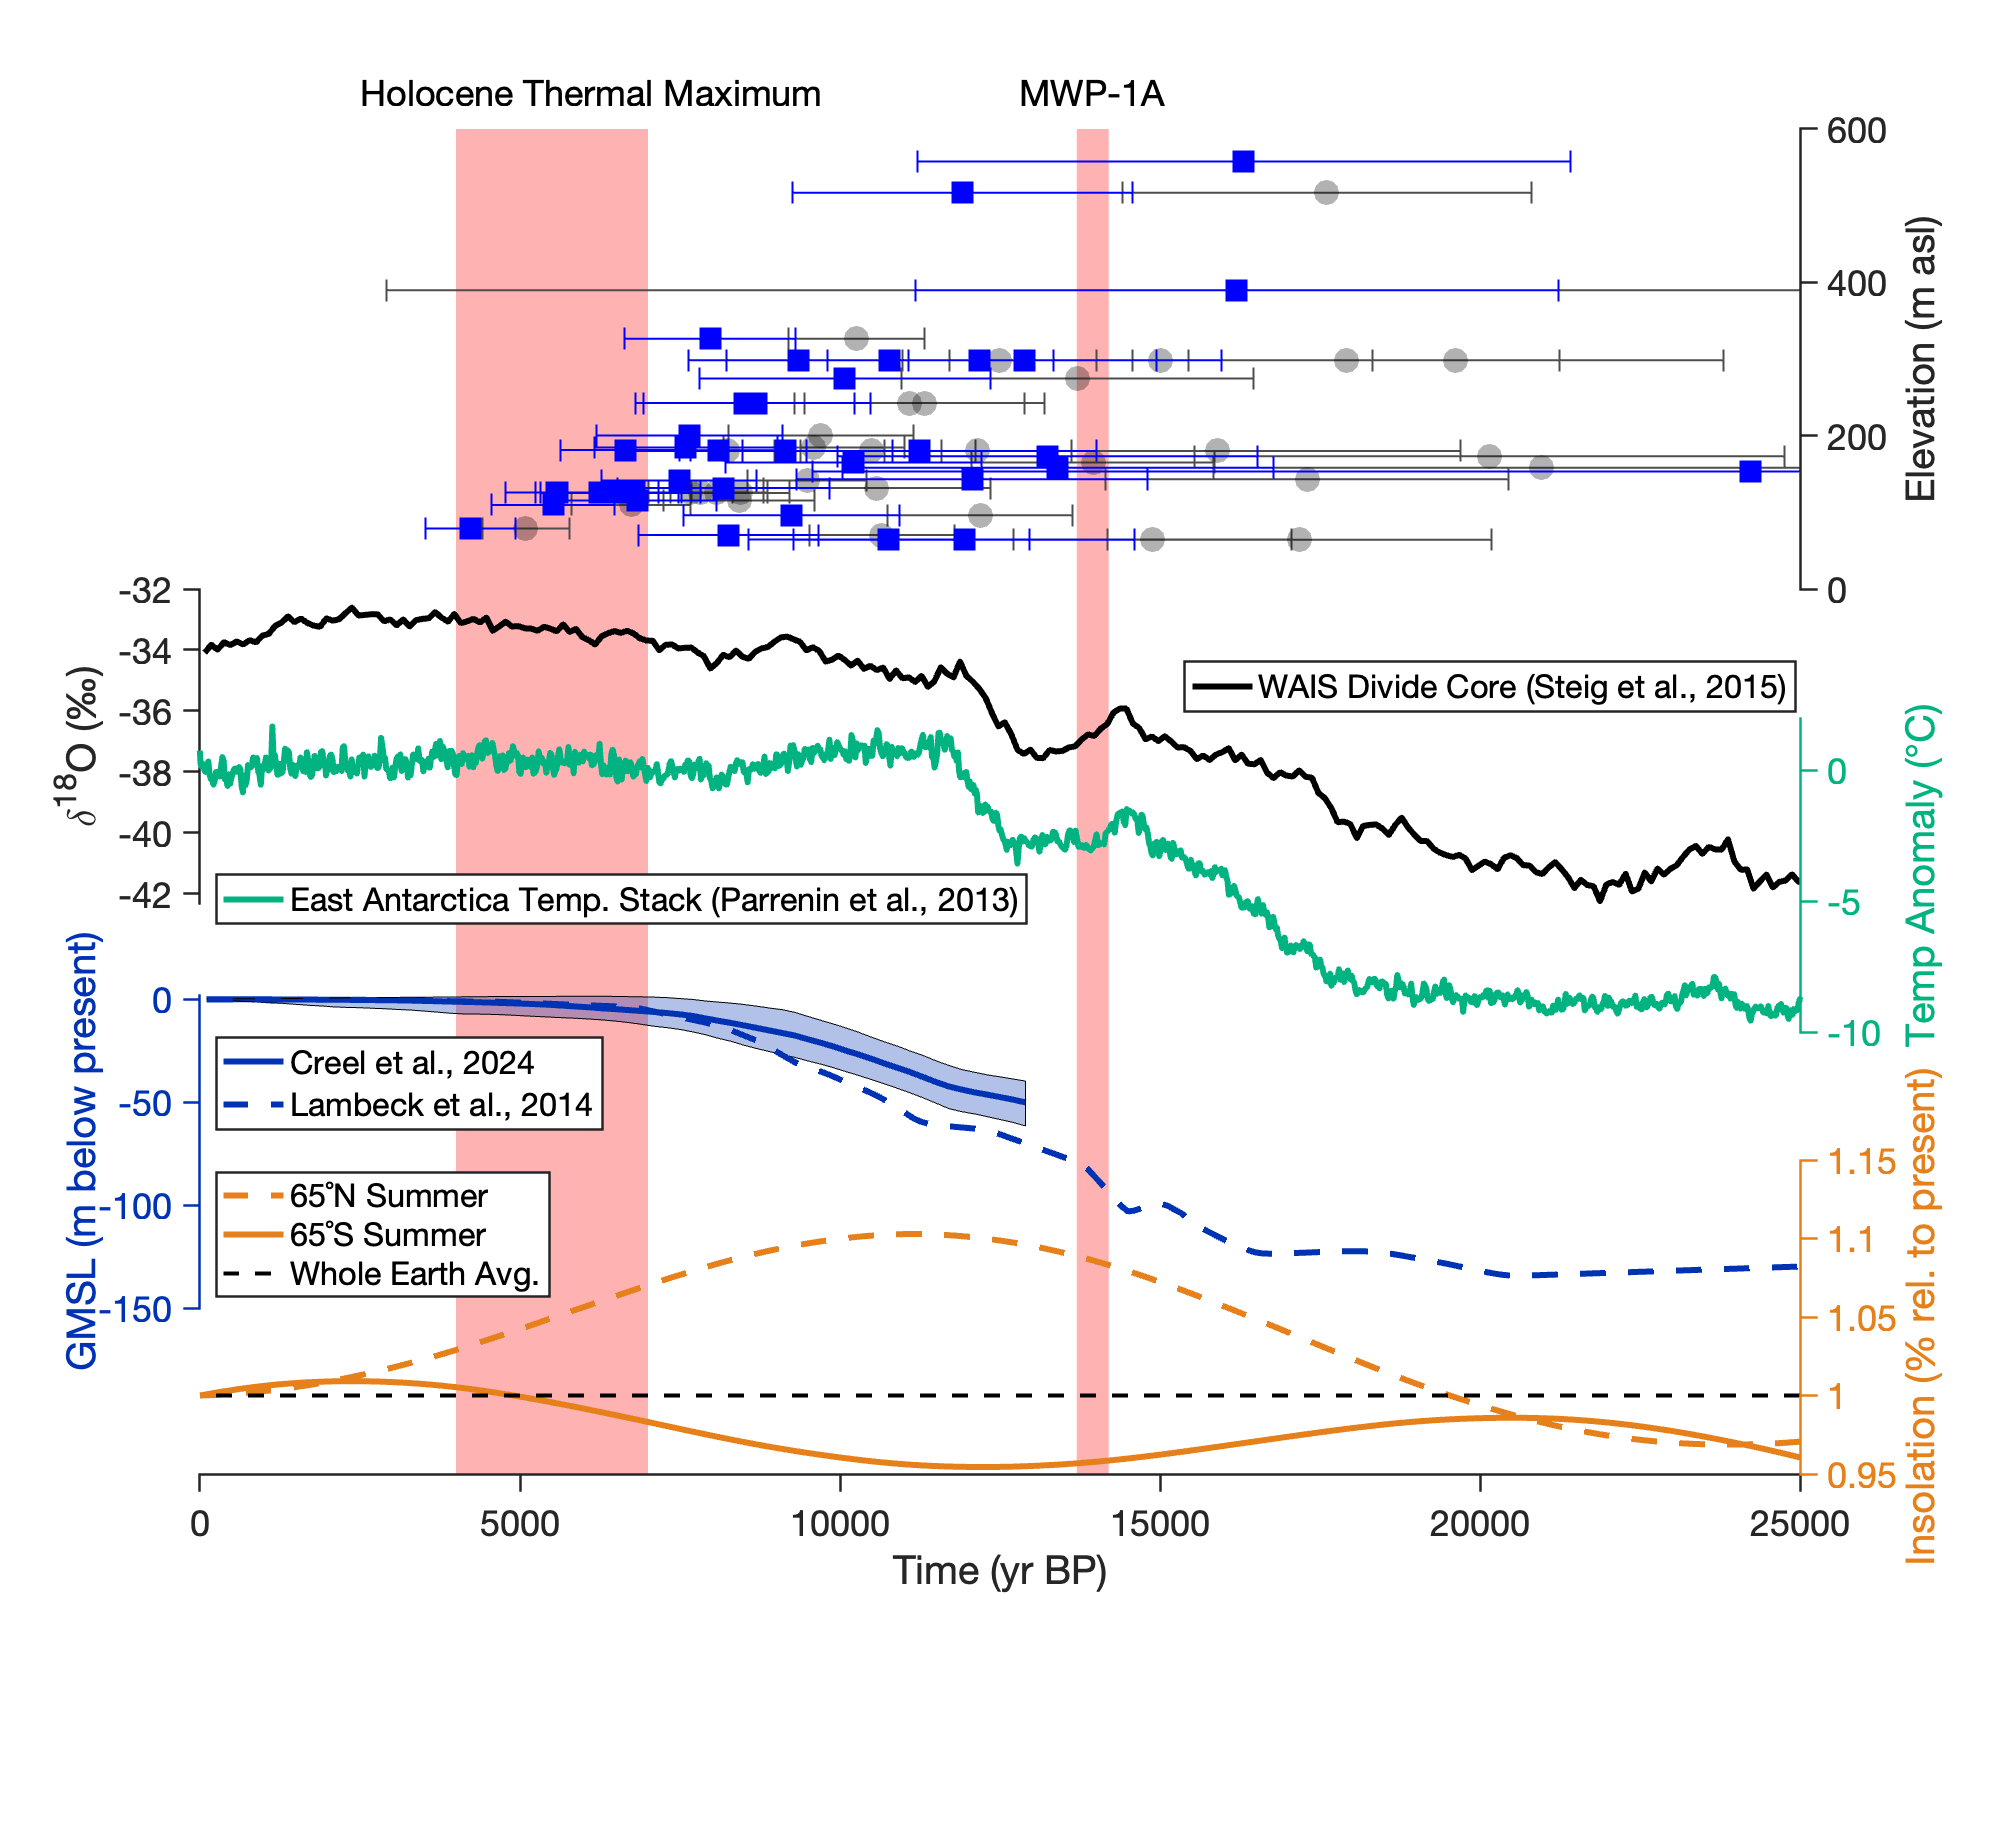

set(0,'DefaultFigureVisible','on');
set(0,'DefaultFigureWindowStyle','normal');   % not docked

fig = figure('Units','pixels','Position',[100 100 1000 1000],'Color','w');

left = 0.1; width = 0.8; h = 0.17;
b1 = 0.98 - 0.3;
b2 = b1 - (h + 0);
b3 = b2 - (h - 0.1);
b4 = b3 - (h - 0.02);
b5 = b4 - (h - 0.08);

ax1 = axes('Position',[left b1 width 0.25], 'Box','off', 'Layer','top'); hold(ax1,'on')
ax2 = axes('Position',[left b2 width h], 'Box','off', 'Layer','top'); hold(ax2,'on')
ax3 = axes('Position',[left b3 width h], 'Box','off', 'Layer','top'); hold(ax3,'on')
ax4 = axes('Position',[left b4 width h], 'Box','off', 'Layer','top'); hold(ax4,'on')
ax5 = axes('Position',[left b5 width h], 'Box','off', 'Layer','top'); hold(ax5,'on')

axes_arr = [ax1 ax2 ax3 ax4 ax5];

%% ---------- ax1 ----------
errorbar(ax1, tam.orig_age, tam.elev, ...
        tam.orig_unc, tam.orig_unc, ...
        'horizontal','LineStyle','none', 'LineWidth', 1, 'Color', [0.3 0.3 0.3 0.4], 'CapSize',10);
scatter(ax1, tam.orig_age,  tam.elev, 160, 'k', 'filled', 'Marker','o', 'MarkerFaceAlpha',0.3);
errorbar(ax1, tam.calib_age, tam.elev, ...
        tam.calib_unc, tam.calib_unc, ...
        'horizontal','LineStyle','none', 'LineWidth', 1, 'Color','b', 'CapSize',10);
scatter(ax1, tam.calib_age, tam.elev, 200, 'b', 'filled', 'Marker','s', 'DisplayName','Trans-Antarctic Mountains');
ylabel(ax1,'Elevation (m asl)');

%% ---------- ax2 ----------
% δ18O on ax2
cla(ax2); hold(ax2,'on');
plot(ax2, data.waisO18.age, data.waisO18.oxy, 'k-', 'LineWidth',3, 'DisplayName', 'WAIS Divide Core (Steig et al., 2015)');
ylabel(ax2,'\delta^{18}O (‰)','Interpreter','tex');
set(ax2,'YAxisLocation','left','YLim',[-42.3 -32], ...
        'TickDir','out','LineWidth',1.25,'FontName','Helvetica', ...
        'Color','none','PositionConstraint','innerposition');
legend(ax2, 'location', [0.598,0.614845021037868,0.293,0.025])

%% ---------- ax3 ----------
ax3_1 = plot(ax3, data.EATA.age, data.EATA.TA, 'Color',[0 0.7 0.5], 'LineWidth',3, 'DisplayName', 'East Antarctica Temp. Stack (Parrenin et al., 2013)');
%scatter(ax3, 19625, -2, 400, 'MarkerFaceColor', [0.3 0.3 0.3], 'MarkerEdgeColor','none');
%scatter(ax3, 12885, -2, 400, 'MarkerFaceColor', 'b', 'MarkerEdgeColor','none');
ylim(ax3, [-10 2]);
ax3.YColor = [0 0.7 0.5];  % color of y-axis and ticks
ax3.YLabel.Color = [0 0.7 0.5];  % color of the y-axis label
ylabel(ax3,'Temp Anomaly (°C)'); yticks([-10 -8 -6 -4 -2 0 1]);
legend(ax3, [ax3_1], 'location', [0.108,0.49945652173913,0.405,0.025])

%% ---------- ax4 ----------
fname = 'collated_all/quantiles/scalefactor_icemod_quants.nc';
esl_all = ncread(fname,'esl');
age     = ncread(fname,'age');
lo  = esl_all(1,:); mid = esl_all(3,:); hi = esl_all(5,:);
age = (age(:) + 0.1) * 1000; lo = lo(:); hi = hi(:);   
mask = ~(isnan(age)|isnan(lo)|isnan(hi)); age=age(mask); lo=lo(mask); hi=hi(mask);
ax4_1 = plot(ax4, age, mid, 'Color',[0 0.2 0.7], 'LineWidth', 3, 'DisplayName', 'Creel et al., 2024');
fill(ax4, [age; flipud(age)], [lo; flipud(hi)], [0 0.2 0.7], 'FaceAlpha', 0.3)
ax4_2 = plot(ax4, data.lambeckSLR.age, data.lambeckSLR.SLR, 'Color',[0 0.2 0.7], 'LineWidth', 3, 'LineStyle', '--','DisplayName', 'Lambeck et al., 2014');
ylabel(ax4,'GMSL (m below present)');
ylim(ax4,[-150 2]);
ax4.YColor = [0 0.2 0.7];  % color of y-axis and ticks
ax4.YLabel.Color = [0 0.2 0.7];  % color of the y-axis label
yticks([-150 -100 -50 0])
legend(ax4, [ax4_1 ax4_2], 'location', [0.108166666666667,0.389003623188406,0.193,0.046195652173913])

%% ---------- ax5 ----------
plot(ax5, data.solin65n.age, data.solin65n.insolref, 'LineWidth',3, 'Color', [0.9 0.5 0.1], 'LineStyle', '--', 'DisplayName', '65˚N Summer');
plot(ax5, data.solin65s.age, data.solin65s.insolref, 'LineWidth',3, 'Color', [0.9 0.5 0.1], 'DisplayName', '65˚S Summer');
plot(ax5, data.solinavg.age, data.solinavg.insolref, 'k--', 'LineWidth',2, 'DisplayName', 'Whole Earth Avg.');
ylabel(ax5,'Insolation (% rel. to present)', 'HorizontalAlignment', 'center');
ylim(ax5,[0.95 1.15]);
yticks([0.95 1 1.05 1.1 1.15])
ax5.YColor = [0.9 0.5 0.1];  % color of y-axis and ticks
ax5.YLabel.Color = [0.9 0.5 0.1];  % color of the y-axis label
xticks([0 5000 10000 15000 20000 25000])
ax5.XAxis.Exponent = 0; xlabel(ax5,'Time (yr BP)');
legend(ax5, 'location', 'northwest')


%% ---------- shared x & formatting ----------
linkaxes(axes_arr,'x');
set([ax1 ax2 ax3 ax4 ax5], 'FontSize',18, 'FontName','Helvetica', ...
    'TickDir','out', 'LineWidth',1.25, 'Color','none');
set([ax1 ax2 ax3 ax4], 'XColor','none','XTick',[]);
xlim([0 25000]);

% y-axis sides (both δ18O and CO2 stay on left)
set([ax1 ax3 ax5],'YAxisLocation','right');
set([ax2 ax4],'YAxisLocation','left');

%% ---------- y-label spacing (restore clean layout) ----------
for ax = [ax2 ax4]
    ax.YLabel.Units = 'normalized'; p = ax.YLabel.Position; p(1) = -0.06; ax.YLabel.Position = p;
end
for ax = [ax1 ax3 ax5]
    ax.YLabel.Units = 'normalized'; p = ax.YLabel.Position; p(1) = 1.06;  ax.YLabel.Position = p;
end


%
%% ---------- background axis for manual-height bands ----------
% Decide exactly which vertical region should show the bands:
Ytop = ax1.Position(2) + ax1.Position(4);   % top of top panel you want covered
Ybot = ax5.Position(2);                     % bottom of lowest panel to cover
bandAx = axes('Position',[left Ybot width (Ytop - Ybot)], ...
    'Color','none','HitTest','off','HandleVisibility','off', ...
    'XLim',[0 25000],'YLim',[0 1], 'XTick',[], 'YTick',[], ...
    'XColor','none','YColor','none','Layer','bottom');

% --- Manually assign the vertical size of each band ---
% y0,y1 are fractions of the bandAx height (0 = bottom, 1 = top)
span_all = [0 1];

bands = [ 4000  7000;
         13700 14200];
cols  = [1 0 0; 1 0 0];
alpha_main = 0.30;

for b = 1:size(bands,1)
    x0 = bands(b,1); x1 = bands(b,2);
    y0y1 = span_all;
    patch(bandAx,[x0 x1 x1 x0],[y0y1(1) y0y1(1) y0y1(2) y0y1(2)], ...
          cols(b,:), 'FaceAlpha',alpha_main, 'EdgeColor','none');
end

% keep behind data and lock x with the other axes
linkaxes([axes_arr bandAx],'x');
% move the entire background axis behind all other axes
uistack(bandAx, 'bottom');

% labels
yl1 = ylim(ax1);
text(ax1,12800,yl1(2)*1.08,'MWP-1A','FontSize',18,'FontName','Helvetica','Clipping','off');
text(ax1, 2500,yl1(2)*1.08,'Holocene Thermal Maximum','FontSize',18,'FontName','Helvetica','Clipping','off');


fig = gcf;

%Turn on to save a high-resolution figure
%print(fig, 'cliamtecomparecalib_CCR.png', '-dpng', '-r600')

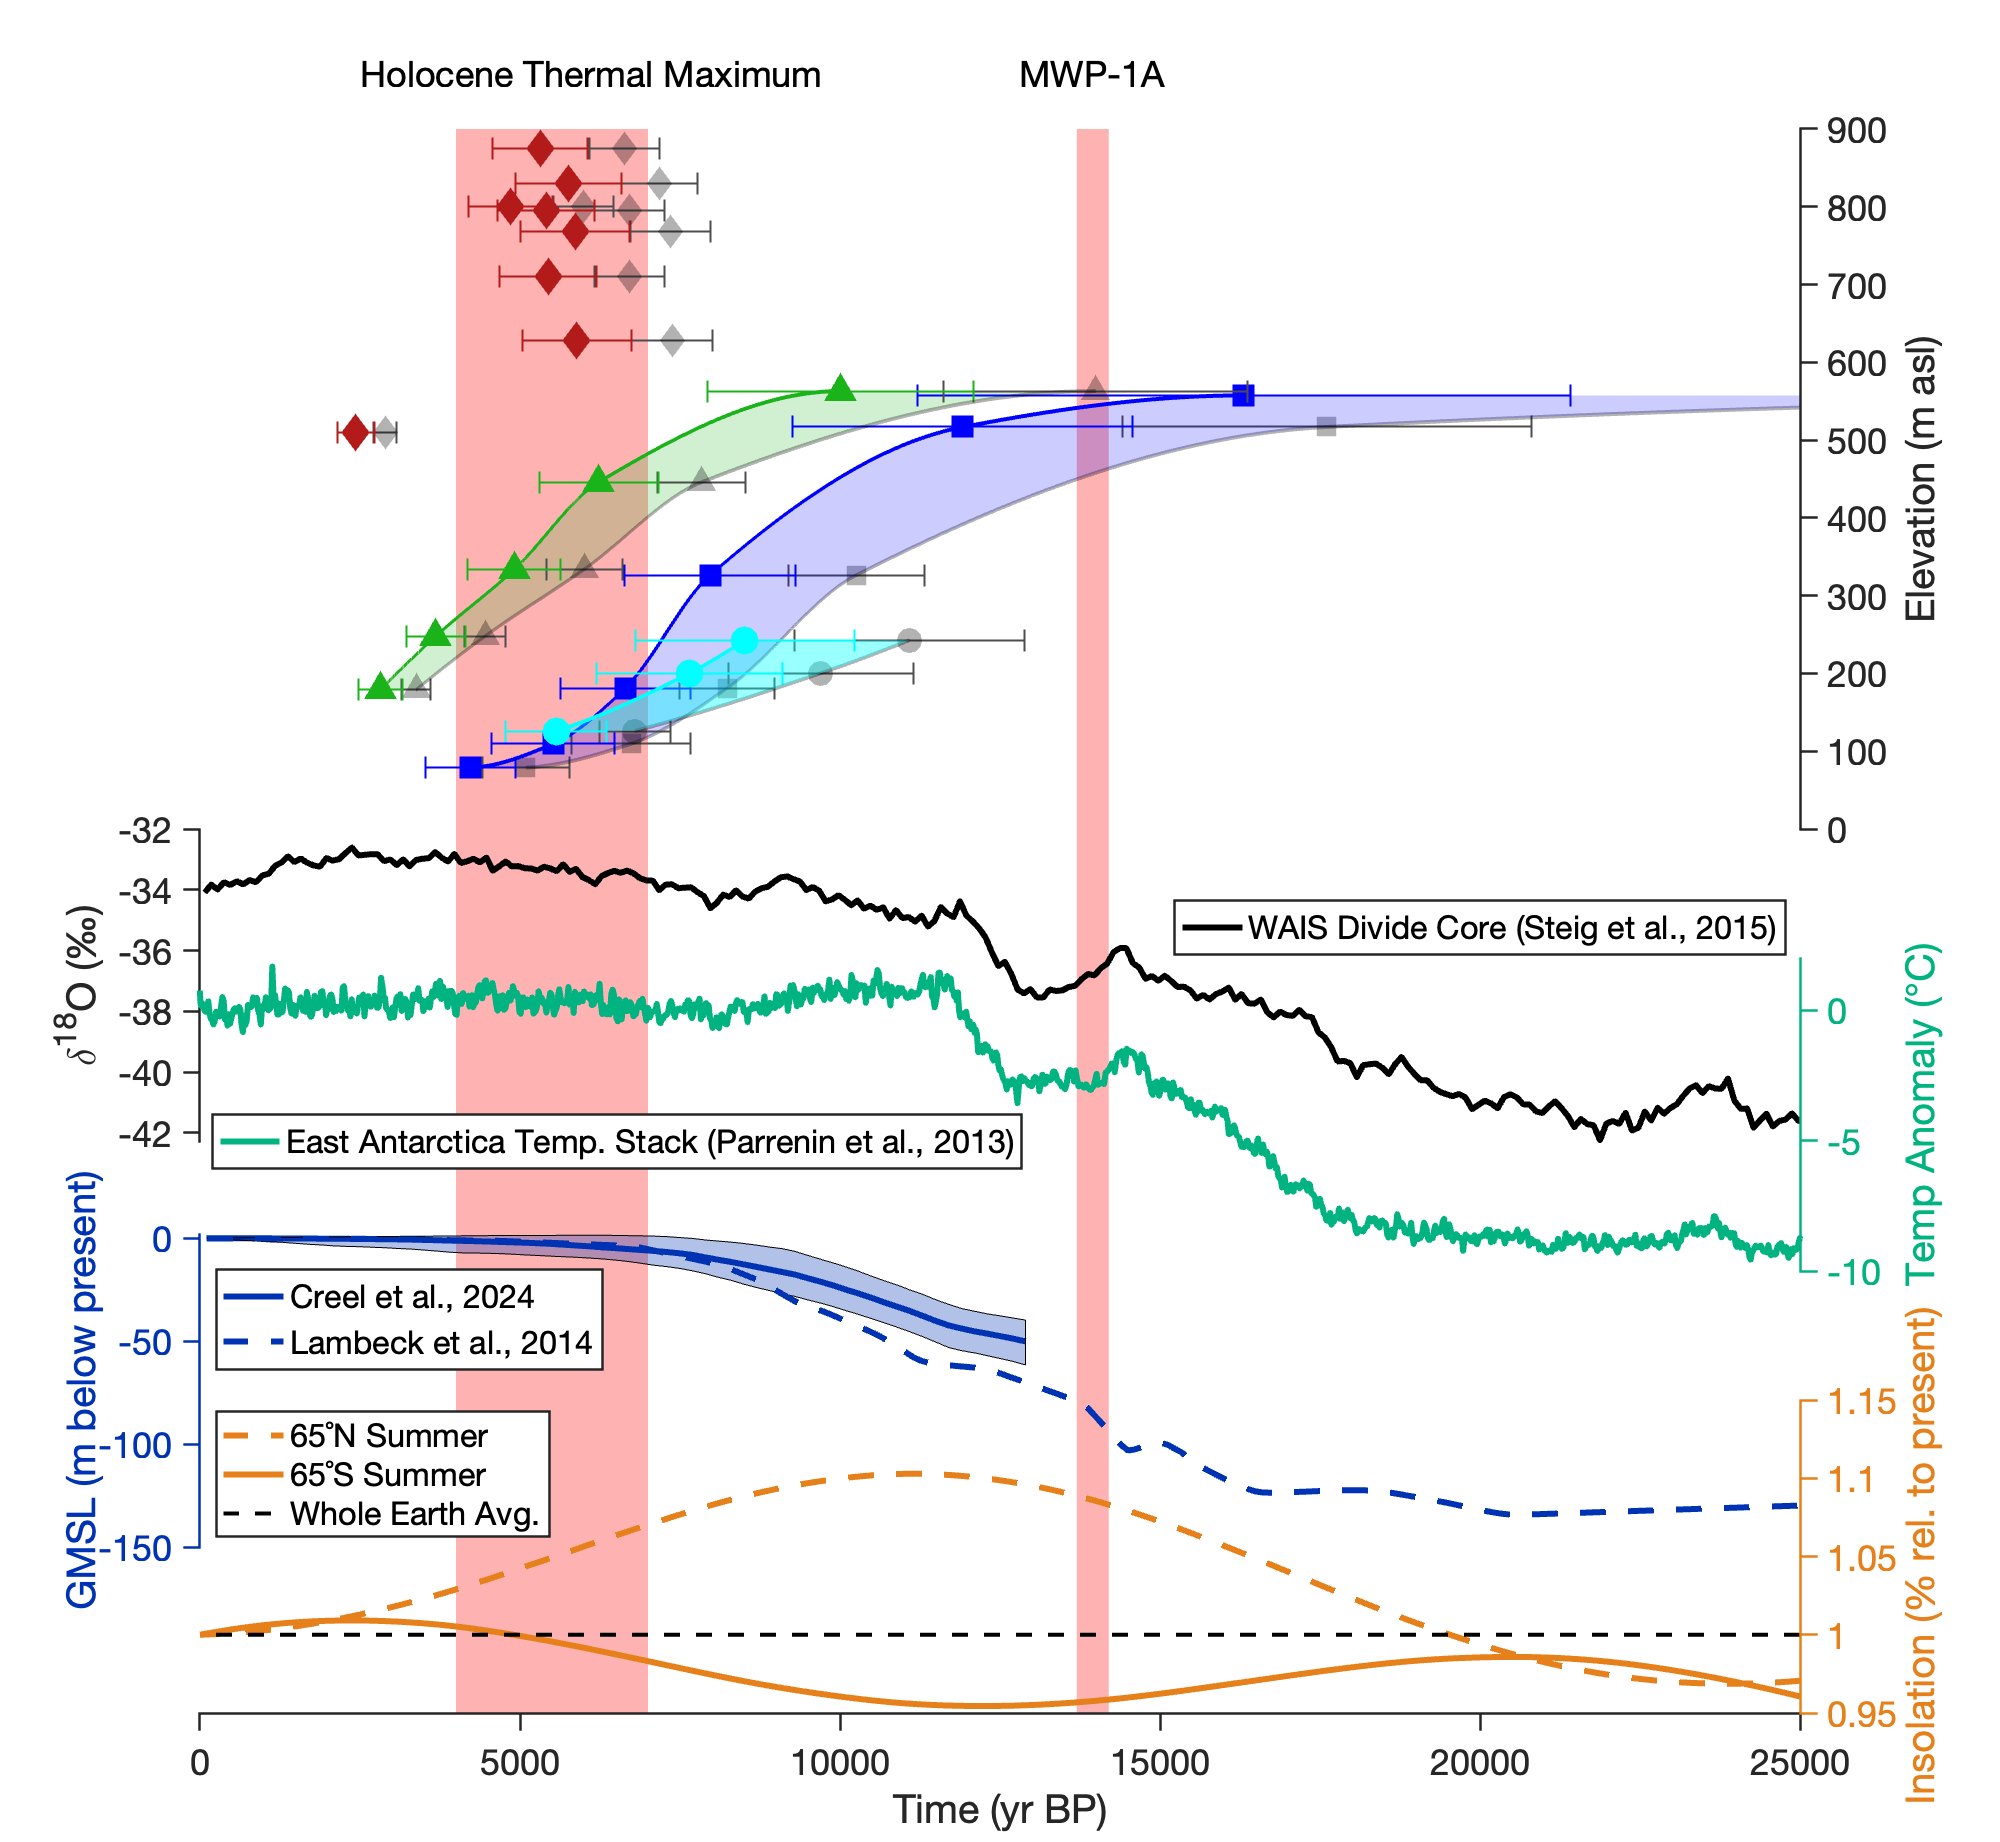

set(0,'DefaultFigureVisible','on');
set(0,'DefaultFigureWindowStyle','normal');   % not docked

fig = figure('Units','pixels','Position',[100 100 1000 1000],'Color','w');

left = 0.1; width = 0.8; h = 0.17;
b1 = 0.98 - 0.43;
b2 = b1 - (h + 0);
b3 = b2 - (h - 0.1);
b4 = b3 - (h - 0.02);
b5 = b4 - (h - 0.08);

ax1 = axes('Position',[left b1 width 0.38], 'Box','off', 'Layer','top'); hold(ax1,'on')
ax2 = axes('Position',[left b2 width h], 'Box','off', 'Layer','top'); hold(ax2,'on')
ax3 = axes('Position',[left b3 width h], 'Box','off', 'Layer','top'); hold(ax3,'on')
ax4 = axes('Position',[left b4 width h], 'Box','off', 'Layer','top'); hold(ax4,'on')
ax5 = axes('Position',[left b5 width h], 'Box','off', 'Layer','top'); hold(ax5,'on')

axes_arr = [ax1 ax2 ax3 ax4 ax5];

%% ---------- ax1 ----------
tam_subset_samples = [1, 2, 12, 13, 14, 15];%, 26];
avg_subset_samples = [18, 20, 22];%, 23];
ase_subset_samples = [3, 17, 22, 27, 29];
for i = tam_subset_samples
    errorbar(ax1, tam.orig_age(i), tam.elev(i), ...
            tam.orig_unc(i), tam.orig_unc(i), ...
            'horizontal','LineStyle','none', 'LineWidth', 1, 'Color', [0.3 0.3 0.3 0.4], 'CapSize',10);
    scatter(ax1, tam.orig_age(i),  tam.elev(i), 160, 'k', 'filled', 'Marker','s', 'MarkerFaceAlpha',0.3);
    errorbar(ax1, tam.calib_age(i), tam.elev(i), ...
            tam.calib_unc(i), tam.calib_unc(i), ...
            'horizontal','LineStyle','none', 'LineWidth', 1, 'Color','b', 'CapSize',10);
    scatter(ax1, tam.calib_age(i), tam.elev(i), 200, 'b', 'filled', 'Marker','s', 'DisplayName','Trans-Antarctic Mountains');
end

% Plot the pchip spline for the TAMs
tam_spline.x_calib = [sort(tam.calib_age(tam_subset_samples),'descend')];
tam_spline.y = [sort(tam.elev(tam_subset_samples), 'descend')];
tam_spline.pp_calib = pchip(tam_spline.x_calib, tam_spline.y);
tam_spline.xx_calib= linspace(4223, 16308, 10000);
plot(ax1, tam_spline.xx_calib, ppval(tam_spline.pp_calib, tam_spline.xx_calib), 'LineWidth', 2, 'Color','b');
tam_spline.yy_calib = ppval(tam_spline.pp_calib, tam_spline.xx_calib);

tam_spline.x_orig = [sort(tam.orig_age(tam_subset_samples),'descend')];
tam_spline.pp_orig = pchip(tam_spline.x_orig, tam_spline.y);
tam_spline.xx_orig = linspace(5089, 38061, 10000);
plot(ax1, tam_spline.xx_orig, ppval(tam_spline.pp_orig, tam_spline.xx_orig), 'LineWidth', 2, 'Color', [0 0 0 0.3]);
tam_spline.yy_orig = ppval(tam_spline.pp_orig, tam_spline.xx_orig);

uistack(fill(ax1, [tam_spline.xx_calib(:); flipud(tam_spline.xx_orig(:))], [tam_spline.yy_calib(:); flipud(tam_spline.yy_orig(:))], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none'), 'top');


for i = avg_subset_samples
    errorbar(ax1, tam.orig_age(i), tam.elev(i), ...
            tam.orig_unc(i), tam.orig_unc(i), ...
            'horizontal','LineStyle','none', 'LineWidth', 1, 'Color', [0.3 0.3 0.3 0.4], 'CapSize',10);
    scatter(ax1, tam.orig_age(i),  tam.elev(i), 160, 'k', 'filled', 'Marker','o', 'MarkerFaceAlpha',0.3);
    errorbar(ax1, tam.calib_age(i), tam.elev(i), ...
            tam.calib_unc(i), tam.calib_unc(i), ...
            'horizontal','LineStyle','none', 'LineWidth', 1, 'Color','c', 'CapSize',10);
    scatter(ax1, tam.calib_age(i), tam.elev(i), 200, 'c', 'filled', 'Marker','o', 'DisplayName','Trans-Antarctic Mountains');
end

% Plot the pchip spline for the AVG
avg_spline.x_calib = [sort(tam.calib_age(avg_subset_samples),'descend')];
avg_spline.y = [sort(tam.elev(avg_subset_samples), 'descend')];
avg_spline.pp_calib = pchip(avg_spline.x_calib, avg_spline.y);
avg_spline.xx_calib= linspace(5568, 8514, 10000);
plot(ax1, avg_spline.xx_calib, ppval(avg_spline.pp_calib, avg_spline.xx_calib), 'LineWidth', 2, 'Color','c');
avg_spline.yy_calib = ppval(avg_spline.pp_calib, avg_spline.xx_calib);

avg_spline.x_orig = [sort(tam.orig_age(avg_subset_samples),'descend')];
avg_spline.pp_orig = pchip(avg_spline.x_orig, avg_spline.y);
avg_spline.xx_orig = linspace(6793, 11085, 10000);
plot(ax1, avg_spline.xx_orig, ppval(avg_spline.pp_orig, avg_spline.xx_orig), 'LineWidth', 2, 'Color', [0 0 0 0.3]);
avg_spline.yy_orig = ppval(avg_spline.pp_orig, avg_spline.xx_orig);

uistack(fill(ax1, [avg_spline.xx_calib(:); flipud(avg_spline.xx_orig(:))], [avg_spline.yy_calib(:); flipud(avg_spline.yy_orig(:))], 'c', 'FaceAlpha', 0.4, 'EdgeColor', 'none'), 'top');


for i = ase_subset_samples
    errorbar(ax1, ase.orig_age(i), ase.elev(i), ...
        ase.orig_unc(i), ase.orig_unc(i), ...
        'horizontal','LineStyle','none', 'LineWidth', 1, 'Color', [0.3 0.3 0.3 0.4], 'CapSize',10);
    scatter(ax1, ase.orig_age(i),  ase.elev(i), 160, 'k', 'filled', 'Marker','^', 'MarkerFaceAlpha',0.3);
    errorbar(ax1, ase.calib_age(i), ase.elev(i), ...
            ase.calib_unc(i), ase.calib_unc(i), ...
            'horizontal','LineStyle','none', 'LineWidth', 1, 'Color',[0.1 0.7 0.1], 'CapSize',10);
    scatter(ax1, ase.calib_age(i), ase.elev(i), 200, [0.1 0.7 0.1], 'filled', 'Marker', '^', 'DisplayName','Trans-Antarctic Mountains');
end

% Plot the pchip spline for the ASE
ase_spline.x_calib = [sort(ase.calib_age(ase_subset_samples),'descend')];
ase_spline.y = [sort(ase.elev(ase_subset_samples), 'descend')];
ase_spline.pp_calib = pchip(ase_spline.x_calib, ase_spline.y);
ase_spline.xx_calib= linspace(2821, 10004, 10000);
plot(ax1, ase_spline.xx_calib, ppval(ase_spline.pp_calib, ase_spline.xx_calib), 'LineWidth', 2, 'Color',[0.1 0.7 0.1]);
ase_spline.yy_calib = ppval(ase_spline.pp_calib, ase_spline.xx_calib);

ase_spline.x_orig = [sort(ase.orig_age(ase_subset_samples),'descend')];
ase_spline.pp_orig = pchip(ase_spline.x_orig, ase_spline.y);
ase_spline.xx_orig = linspace(3376, 13996, 10000);
plot(ax1, ase_spline.xx_orig, ppval(ase_spline.pp_orig, ase_spline.xx_orig), 'LineWidth', 2, 'Color', [0 0 0 0.3]);
ase_spline.yy_orig = ppval(ase_spline.pp_orig, ase_spline.xx_orig);

uistack(fill(ax1, [ase_spline.xx_calib(:); flipud(ase_spline.xx_orig(:))], [ase_spline.yy_calib(:); flipud(ase_spline.yy_orig(:))], [0.1 0.7 0.1], 'FaceAlpha', 0.2, 'EdgeColor', 'none'), 'bottom');

errorbar(ax1, las.orig_age, las.elev, ...
        las.orig_unc, las.orig_unc, ...
        'horizontal','LineStyle','none', 'LineWidth', 1, 'Color', [0.3 0.3 0.3 0.4], 'CapSize',10);
scatter(ax1, las.orig_age,  las.elev, 160, 'k', 'filled', 'Marker','d', 'MarkerFaceAlpha',0.3);
errorbar(ax1, las.calib_age, las.elev, ...
        las.calib_unc, las.calib_unc, ...
        'horizontal','LineStyle','none', 'LineWidth', 1, 'Color',[0.7 0.1 0.1], 'CapSize',10);
scatter(ax1, las.calib_age, las.elev, 200, [0.7 0.1 0.1], 'filled', 'Marker', 'd', 'DisplayName','Trans-Antarctic Mountains');

ylabel(ax1,'Elevation (m asl)');

%% ---------- ax2 ----------
% δ18O on ax2
cla(ax2); hold(ax2,'on');
plot(ax2, data.waisO18.age, data.waisO18.oxy, 'k-', 'LineWidth',3, 'DisplayName', 'WAIS Divide Core (Steig et al., 2015)');
ylabel(ax2,'\delta^{18}O (‰)','Interpreter','tex');
set(ax2,'YAxisLocation','left','YLim',[-42.3 -32], ...
        'TickDir','out','LineWidth',1.25,'FontName','Helvetica', ...
        'Color','none','PositionConstraint','innerposition');
legend(ax2, 'location', [0.58675,0.483323281907433,0.3055,0.027173913043479])

%% ---------- ax3 ----------
ax3_1 = plot(ax3, data.EATA.age, data.EATA.TA, 'Color',[0 0.7 0.5], 'LineWidth',3, 'DisplayName', 'East Antarctica Temp. Stack (Parrenin et al., 2013)');
%scatter(ax3, 19625, -2, 400, 'MarkerFaceColor', [0.3 0.3 0.3], 'MarkerEdgeColor','none');
%scatter(ax3, 12885, -2, 400, 'MarkerFaceColor', 'b', 'MarkerEdgeColor','none');
ylim(ax3, [-10 2]);
ax3.YColor = [0 0.7 0.5];  % color of y-axis and ticks
ax3.YLabel.Color = [0 0.7 0.5];  % color of the y-axis label
ylabel(ax3,'Temp Anomaly (°C)'); yticks([-10 -8 -6 -4 -2 0 1]);
legend(ax3, [ax3_1], 'location', [0.106,0.366847826086956,0.405,0.027173913043478])

%% ---------- ax4 ----------
fname = 'collated_all/quantiles/scalefactor_icemod_quants.nc';
esl_all = ncread(fname,'esl');
age     = ncread(fname,'age');
lo  = esl_all(1,:); mid = esl_all(3,:); hi = esl_all(5,:);
age = (age(:) + 0.1) * 1000; lo = lo(:); hi = hi(:);   
mask = ~(isnan(age)|isnan(lo)|isnan(hi)); age=age(mask); lo=lo(mask); hi=hi(mask);
ax4_1 = plot(ax4, age, mid, 'Color',[0 0.2 0.7], 'LineWidth', 3, 'DisplayName', 'Creel et al., 2024');
fill(ax4, [age; flipud(age)], [lo; flipud(hi)], [0 0.2 0.7], 'FaceAlpha', 0.3)
ax4_2 = plot(ax4, data.lambeckSLR.age, data.lambeckSLR.SLR, 'Color',[0 0.2 0.7], 'LineWidth', 3, 'LineStyle', '--','DisplayName', 'Lambeck et al., 2014');
ylabel(ax4,'GMSL (m below present)');
ylim(ax4,[-150 2]);
ax4.YColor = [0 0.2 0.7];  % color of y-axis and ticks
ax4.YLabel.Color = [0 0.2 0.7];  % color of the y-axis label
yticks([-150 -100 -50 0])
legend(ax4, [ax4_1 ax4_2], 'location', [0.108166666666667,0.258734247006931,0.193,0.050212665406427])

%% ---------- ax5 ----------
plot(ax5, data.solin65n.age, data.solin65n.insolref, 'LineWidth',3, 'Color', [0.9 0.5 0.1], 'LineStyle', '--', 'DisplayName', '65˚N Summer');
plot(ax5, data.solin65s.age, data.solin65s.insolref, 'LineWidth',3, 'Color', [0.9 0.5 0.1], 'DisplayName', '65˚S Summer');
plot(ax5, data.solinavg.age, data.solinavg.insolref, 'k--', 'LineWidth',2, 'DisplayName', 'Whole Earth Avg.');
ylabel(ax5,'Insolation (% rel. to present)', 'HorizontalAlignment', 'center');
ylim(ax5,[0.95 1.15]);
yticks([0.95 1 1.05 1.1 1.15])
ax5.YColor = [0.9 0.5 0.1];  % color of y-axis and ticks
ax5.YLabel.Color = [0.9 0.5 0.1];  % color of the y-axis label
xticks([0 5000 10000 15000 20000 25000])
ax5.XAxis.Exponent = 0; xlabel(ax5,'Time (yr BP)');
legend(ax5, 'location', 'northwest')


%% ---------- shared x & formatting ----------
linkaxes(axes_arr,'x');
set([ax1 ax2 ax3 ax4 ax5], 'FontSize',18, 'FontName','Helvetica', ...
    'TickDir','out', 'LineWidth',1.25, 'Color','none');
set([ax1 ax2 ax3 ax4], 'XColor','none','XTick',[]);
xlim([0 25000]);

% y-axis sides (both δ18O and CO2 stay on left)
set([ax1 ax3 ax5],'YAxisLocation','right');
set([ax2 ax4],'YAxisLocation','left');

%% ---------- y-label spacing (restore clean layout) ----------
for ax = [ax2 ax4]
    ax.YLabel.Units = 'normalized'; p = ax.YLabel.Position; p(1) = -0.06; ax.YLabel.Position = p;
end
for ax = [ax1 ax3 ax5]
    ax.YLabel.Units = 'normalized'; p = ax.YLabel.Position; p(1) = 1.06;  ax.YLabel.Position = p;
end


%
%% ---------- background axis for manual-height bands ----------
% Decide exactly which vertical region should show the bands:
Ytop = ax1.Position(2) + ax1.Position(4);   % top of top panel you want covered
Ybot = ax5.Position(2);                     % bottom of lowest panel to cover
bandAx = axes('Position',[left Ybot width (Ytop - Ybot)], ...
    'Color','none','HitTest','off','HandleVisibility','off', ...
    'XLim',[0 25000],'YLim',[0 1], 'XTick',[], 'YTick',[], ...
    'XColor','none','YColor','none','Layer','bottom');

% --- Manually assign the vertical size of each band ---
% y0,y1 are fractions of the bandAx height (0 = bottom, 1 = top)
span_all = [0 1];

bands = [ 4000  7000;
         13700 14200];
cols  = [1 0 0; 1 0 0];
alpha_main = 0.30;

for b = 1:size(bands,1)
    x0 = bands(b,1); x1 = bands(b,2);
    y0y1 = span_all;
    patch(bandAx,[x0 x1 x1 x0],[y0y1(1) y0y1(1) y0y1(2) y0y1(2)], ...
          cols(b,:), 'FaceAlpha',alpha_main, 'EdgeColor','none');
end

% keep behind data and lock x with the other axes
linkaxes([axes_arr bandAx],'x');
% move the entire background axis behind all other axes
uistack(bandAx, 'bottom');

% labels
yl1 = ylim(ax1);
text(ax1,12800,yl1(2)*1.08,'MWP-1A','FontSize',18,'FontName','Helvetica','Clipping','off');
text(ax1, 2500,yl1(2)*1.08,'Holocene Thermal Maximum','FontSize',18,'FontName','Helvetica','Clipping','off');


fig = gcf;
%Turn on to save a high-resolution figure
%print(fig, 'finaldiscussionfigure.png', '-dpng', '-r600')


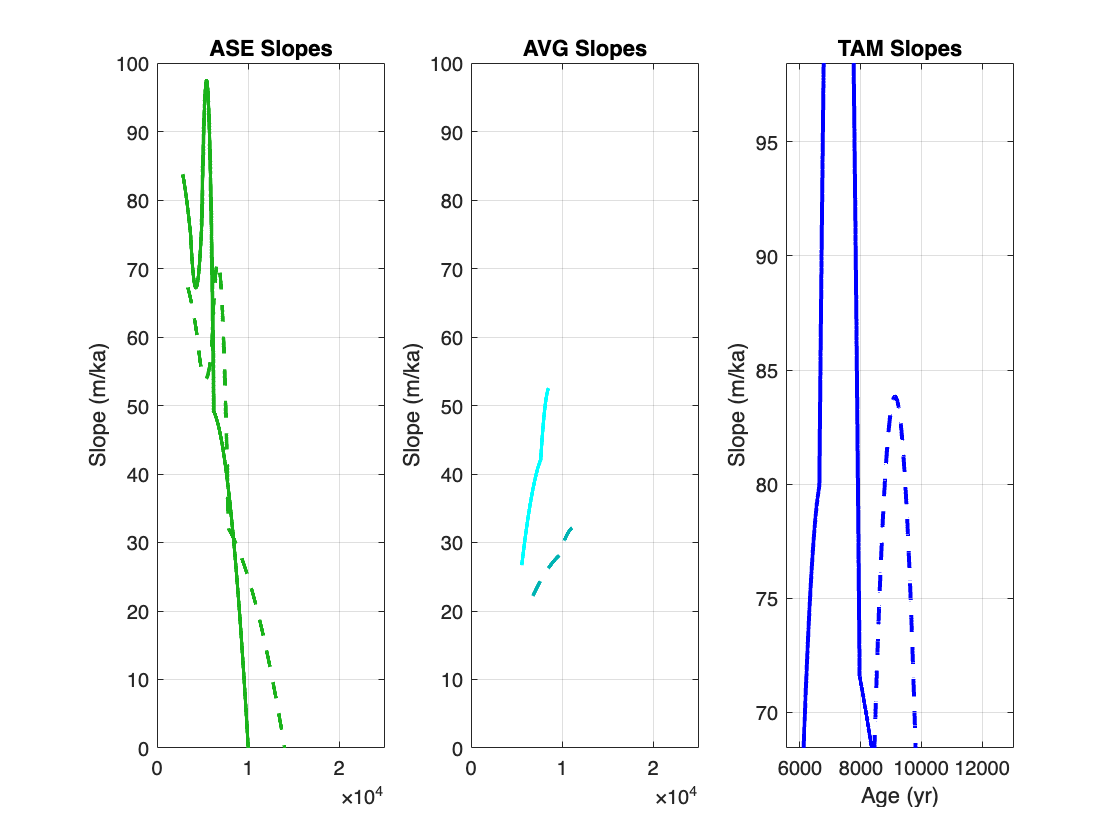

% ===== Compute spline slopes (m/kyr) =====
% ASE
ase_spline.pp_calib_deriv = fnder(ase_spline.pp_calib);
ase_spline.slope_calib = ppval(ase_spline.pp_calib_deriv, ase_spline.xx_calib) * 1000;
ase_spline.pp_orig_deriv = fnder(ase_spline.pp_orig);
ase_spline.slope_orig = ppval(ase_spline.pp_orig_deriv, ase_spline.xx_orig) * 1000;

% AVG
avg_spline.pp_calib_deriv = fnder(avg_spline.pp_calib);
avg_spline.slope_calib = ppval(avg_spline.pp_calib_deriv, avg_spline.xx_calib) * 1000;
avg_spline.pp_orig_deriv = fnder(avg_spline.pp_orig);
avg_spline.slope_orig = ppval(avg_spline.pp_orig_deriv, avg_spline.xx_orig) * 1000;

% TAM
tam_spline.pp_calib_deriv = fnder(tam_spline.pp_calib);
tam_spline.slope_calib = ppval(tam_spline.pp_calib_deriv, tam_spline.xx_calib) * 1000;
tam_spline.pp_orig_deriv = fnder(tam_spline.pp_orig);
tam_spline.slope_orig = ppval(tam_spline.pp_orig_deriv, tam_spline.xx_orig) * 1000;

% ===== Plot slopes as subplots =====
figure('Color','w');

% --- ASE ---
subplot(1,3,1); hold on; box on;
plot(ase_spline.xx_calib, ase_spline.slope_calib, 'LineWidth',2, 'Color',[0.1 0.7 0.1]);
plot(ase_spline.xx_orig,  ase_spline.slope_orig,  '--', 'LineWidth',2, 'Color',[0.1 0.7 0.1 0.6]);
xlim([0 25000]); ylim([0 100]);
ylabel('Slope (m/ka)');
title('ASE Slopes');
grid on;

% --- AVG ---
subplot(1,3,2); hold on; box on;
plot(avg_spline.xx_calib, avg_spline.slope_calib, 'LineWidth',2, 'Color','c');
plot(avg_spline.xx_orig,  avg_spline.slope_orig,  '--', 'LineWidth',2, 'Color',[0 0.7 0.7 0.6]);
xlim([0 25000]); ylim([0 100]);
ylabel('Slope (m/ka)');
title('AVG Slopes');
grid on;

% --- TAM ---
subplot(1,3,3); hold on; box on;
plot(tam_spline.xx_calib, tam_spline.slope_calib, 'LineWidth',2, 'Color','b');
plot(tam_spline.xx_orig,  tam_spline.slope_orig,  '--', 'LineWidth',2, 'Color',[0 0 1 0.6]);
xlim([0 25000]); ylim([0 100]);
xlabel('Age (yr)');
ylabel('Slope (m/ka)');
title('TAM Slopes');


grid on;

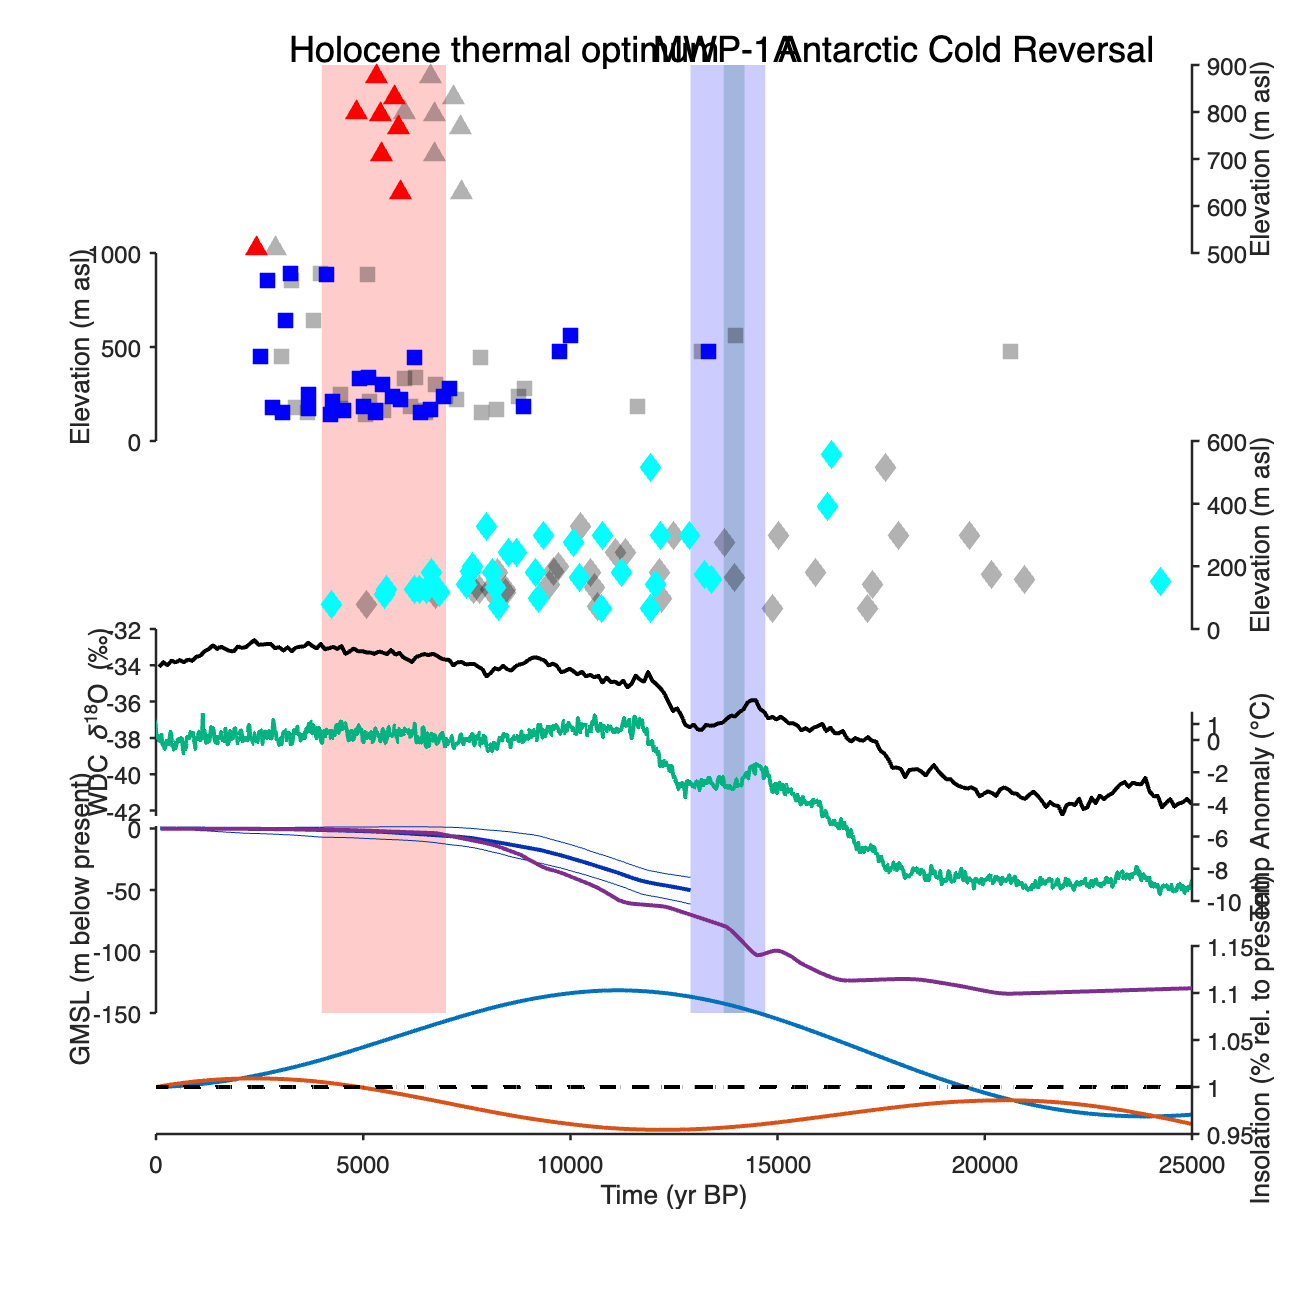

fig = figure('Units','pixels','Position',[100 100 1000 1000],'Color','w');

left = 0.12; width = 0.80; h = 0.145; gap = 0.0;
b1 = 0.95 - h;
b2 = b1 - (h + gap);
b3 = b2 - (h + gap);
b4 = b3 - (h + gap);
b5 = b4 - (h + 0.1);
b6 = b5 - (h - 0.25);
b7 = b4 - (h - 0.08);

ax1 = axes('Position',[left b1 width h], 'Box','off', 'Layer','top'); hold(ax1,'on')
ax2 = axes('Position',[left b2 width h], 'Box','off', 'Layer','top'); hold(ax2,'on')
ax3 = axes('Position',[left b3 width h], 'Box','off', 'Layer','top'); hold(ax3,'on')
ax4 = axes('Position',[left b4 width h], 'Box','off', 'Layer','top'); hold(ax4,'on')   % <- keep this one
ax5 = axes('Position',[left b5 width h], 'Box','off', 'Layer','top'); hold(ax5,'on')
ax6 = axes('Position',[left b6 width h], 'Box','off', 'Layer','top'); hold(ax6,'on')
ax7 = axes('Position',[left b7 width h], 'Box','off', 'Layer','top'); hold(ax7,'on')

axes_arr = [ax1 ax2 ax3 ax4 ax5 ax6 ax7];

%% ---------- data ----------
% ax1
scatter(ax1, las.orig_age,  las.elev, 100, 'k^', 'filled', 'MarkerFaceAlpha',0.3);
scatter(ax1, las.calib_age, las.elev, 100, 'r^', 'filled', 'DisplayName','Lassiter Coast');
ylabel(ax1,'Elevation (m asl)');

% ax2
scatter(ax2, ase.orig_age,  ase.elev, 100, 'k', 'filled', 'Marker','s', 'MarkerFaceAlpha',0.3);
scatter(ax2, ase.calib_age, ase.elev, 100, 'b', 'filled', 'Marker','s', 'DisplayName','Amundsen Sea Embayment');
ylabel(ax2,'Elevation (m asl)');

% ax3
scatter(ax3, tam.orig_age,  tam.elev, 100, 'k', 'filled', 'Marker','d', 'MarkerFaceAlpha',0.3);
scatter(ax3, tam.calib_age, tam.elev, 100, 'c', 'filled', 'Marker','d', 'DisplayName','Trans-Antarctic Mountains');
ylabel(ax3,'Elevation (m asl)');

%% ---------- δ18O (primary) + CO2 (overlay; both left, ticks out) ----------
% δ18O on ax4
cla(ax4); hold(ax4,'on');
plot(ax4, data.waisO18.age, data.waisO18.oxy, 'k-', 'LineWidth',2);
ylabel(ax4,'WDC \delta^{18}O (‰)','Interpreter','tex');
set(ax4,'YAxisLocation','left','YLim',[-42.3 -32], ...
        'TickDir','out','LineWidth',1.25,'FontName','Helvetica', ...
        'Color','none','PositionConstraint','innerposition');



%% ---------- ax5 ----------
plot(ax5, data.solin65n.age, data.solin65n.insolref, 'LineWidth',2);
plot(ax5, data.solin65s.age, data.solin65s.insolref, 'LineWidth',2);
plot(ax5, data.solinavg.age, data.solinavg.insolref, 'k--', 'LineWidth',2);
ylabel(ax5,'Insolation (% rel. to present)');
ylim(ax5,[0.95 1.15]);

%% ---------- ax6 ----------
fname = 'collated_all/quantiles/scalefactor_icemod_quants.nc';
esl_all = ncread(fname,'esl');   % (quantile, time)
age     = ncread(fname,'age');   % kyr BP (assumed)
lo  = esl_all(1,:); mid = esl_all(3,:); hi = esl_all(5,:);
age = (age(:) + 0.1) * 1000; lo = lo(:); hi = hi(:);    % years BP, columns
mask = ~(isnan(age)|isnan(lo)|isnan(hi)); age=age(mask); lo=lo(mask); hi=hi(mask);
plot(ax6, age, mid, 'Color',[0 0.2 0.7], 'LineWidth',2);
plot(ax6, age, lo,  'Color',[0 0.2 0.7], 'LineWidth',0.5);
plot(ax6, age, hi,  'Color',[0 0.2 0.7], 'LineWidth',0.5);
plot(ax6, data.lambeckSLR.age, data.lambeckSLR.SLR, 'LineWidth', 2);
ylabel(ax6,'GMSL (m below present)');
ylim(ax6,[-150 2]);
% tiny vertical nudge for GMSL axis
p6 = ax6.Position; p6(2) = p6(2) - 0.012; set(ax6,'Position',p6);

%% ---------- ax7 ----------
plot(ax7, data.EATA.age, data.EATA.TA, 'Color',[0 0.7 0.5], 'LineWidth',2)
ylabel(ax7,'Temp Anomaly (°C)'); yticks([-10 -8 -6 -4 -2 0 1]);

%% ---------- shared x & formatting ----------
linkaxes(axes_arr,'x');
set([ax1 ax2 ax3 ax4 ax5 ax6 ax7], 'FontSize',12, 'FontName','Helvetica', ...
    'TickDir','out', 'LineWidth',1.25, 'Color','none');
set([ax1 ax2 ax3 ax4 ax6 ax7], 'XColor','none','XTick',[]);
xlim([0 25000]);
ax5.XAxis.Exponent = 0; xlabel(ax5,'Time (yr BP)');

% y-axis sides (both δ18O and CO2 stay on left)
set([ax1 ax3 ax5 ax7],'YAxisLocation','right');
set([ax2 ax4 ax6],'YAxisLocation','left');

%% ---------- y-label spacing (restore clean layout) ----------
for ax = [ax2 ax4 ax6]
    ax.YLabel.Units = 'normalized'; p = ax.YLabel.Position; p(1) = -0.06; ax.YLabel.Position = p;
end
for ax = [ax1 ax3 ax5 ax7]
    ax.YLabel.Units = 'normalized'; p = ax.YLabel.Position; p(1) = 1.05;  ax.YLabel.Position = p;
end

% === Final δ18O / CO2 label placement & overlay axis cosmetics ===
ylabel(ax4, 'WDC \delta^{18}O (‰)', 'Interpreter','tex');     % ensure text set




% Final label placements (override the spacing loop)
ax4.YLabel.Units  = 'normalized'; p = ax4.YLabel.Position;  p(1) = -0.04; ax4.YLabel.Position  = p;   % δ18O snug to spine
set(axes_arr,'TickLength',[0.006 0.006]);

%
%% ---------- background axis for manual-height bands ----------
% Decide exactly which vertical region should show the bands:
Ytop = ax1.Position(2) + ax1.Position(4);   % top of top panel you want covered
Ybot = ax6.Position(2);                     % bottom of lowest panel to cover
bandAx = axes('Position',[left Ybot width (Ytop - Ybot)], ...
    'Color','none','HitTest','off','HandleVisibility','off', ...
    'XLim',[0 25000],'YLim',[0 1], 'XTick',[], 'YTick',[], ...
    'XColor','none','YColor','none','Layer','bottom');

% --- Manually assign the vertical size of each band ---
% y0,y1 are fractions of the bandAx height (0 = bottom, 1 = top)
% Example 1: cover ALL selected panels uniformly:
span_all = [0 1];

% Example 2 (custom): different vertical heights per band (no overlap):
spans = [0.00 1.00;
         0.00 1.00;
         0.00 1.00];

bands = [ 4000  7000;
         13700 14200;
         12900 14700];
cols  = [1 0 0; 0 0.45 0.2; 0 0 1];
alpha_main = 0.20;

for b = 1:size(bands,1)
    x0 = bands(b,1); x1 = bands(b,2);
    % choose either one span for all bands, or per-band spans(b,:)
    y0y1 = spans(b,:);            % <- use 'span_all' instead if you want same height
    patch(bandAx,[x0 x1 x1 x0],[y0y1(1) y0y1(1) y0y1(2) y0y1(2)], ...
          cols(b,:), 'FaceAlpha',alpha_main, 'EdgeColor','none');
end

% keep behind data and lock x with the other axes
uistack(bandAx,'bottom');
linkaxes([axes_arr bandAx],'x');


% labels
yl1 = ylim(ax1);
text(ax1,12000,yl1(2)*1.04,'MWP-1A','FontSize',18,'FontName','Helvetica','Clipping','off');
text(ax1, 3200,yl1(2)*1.04,'Holocene thermal optimum','FontSize',18,'FontName','Helvetica','Clipping','off');
text(ax1,15000,yl1(2)*1.04,'Antarctic Cold Reversal','FontSize',18,'FontName','Helvetica','Clipping','off');

fig = figure('Units','pixels','Position',[100 100 1000 1000],'Color','w');

left = 0.12; width = 0.80; h = 0.145; gap = 0.0;
b1 = 0.95 - h;
b2 = b1 - (h + gap);
b3 = b2 - (h + gap);
b4 = b3 - (h + gap);
b5 = b4 - (h + 0.1);
b6 = b5 - (h - 0.25);
b7 = b4 - (h - 0.08);

ax1 = axes('Position',[left b1 width h], 'Box','off', 'Layer','top'); hold(ax1,'on')
ax2 = axes('Position',[left b2 width h], 'Box','off', 'Layer','top'); hold(ax2,'on')
ax3 = axes('Position',[left b3 width h], 'Box','off', 'Layer','top'); hold(ax3,'on')
ax4 = axes('Position',[left b4 width h], 'Box','off', 'Layer','top'); hold(ax4,'on')   % <- keep this one
ax5 = axes('Position',[left b5 width h], 'Box','off', 'Layer','top'); hold(ax5,'on')
ax6 = axes('Position',[left b6 width h], 'Box','off', 'Layer','top'); hold(ax6,'on')
ax7 = axes('Position',[left b7 width h], 'Box','off', 'Layer','top'); hold(ax7,'on')

axes_arr = [ax1 ax2 ax3 ax4 ax5 ax6 ax7];

%% ---------- data ----------
% ax1
scatter(ax1, las.orig_age,  las.elev, 100, 'k^', 'filled', 'MarkerFaceAlpha',0.3);
scatter(ax1, las.calib_age, las.elev, 100, 'r^', 'filled', 'DisplayName','Lassiter Coast');
ylabel(ax1,'Elevation (m asl)');

% ax2
scatter(ax2, ase.orig_age,  ase.elev, 100, 'k', 'filled', 'Marker','s', 'MarkerFaceAlpha',0.3);
scatter(ax2, ase.calib_age, ase.elev, 100, 'b', 'filled', 'Marker','s', 'DisplayName','Amundsen Sea Embayment');
ylabel(ax2,'Elevation (m asl)');

% ax3
scatter(ax3, tam.orig_age,  tam.elev, 100, 'k', 'filled', 'Marker','d', 'MarkerFaceAlpha',0.3);
scatter(ax3, tam.calib_age, tam.elev, 100, 'c', 'filled', 'Marker','d', 'DisplayName','Trans-Antarctic Mountains');
ylabel(ax3,'Elevation (m asl)');


%% δ18O (primary) + CO2 (overlay; both left, ticks out, spine effectively hidden)

% -- δ18O primary on ax4 --
cla(ax4); hold(ax4,'on');
plot(ax4, data.waisO18.age, data.waisO18.oxy, 'k-', 'LineWidth', 2);
ylabel(ax4,'WDC \delta^{18}O (‰)','Interpreter','tex');
set(ax4,'YAxisLocation','left','YLim',[-42.3 -32], ...
        'TickDir','out','LineWidth',1.25,'FontName','Helvetica', ...
        'Color','none','PositionConstraint','innerposition');

% cache geometry of the inner data box (to keep perfect alignment)
ip = ax4.InnerPosition;   % inner/data box
p  = ax4.Position;        % outer box

% -- CO2 overlay axis: same inner box; shift its outer box left for room --
dx   = 0.075;  % try 0.06–0.09 to taste
ax4b = axes('Parent', gcf, 'Color','none','Box','off','Layer','top', ...
            'YAxisLocation','left','XColor','none','TickDir','out', ...
            'FontName','Helvetica','PositionConstraint','innerposition', ...
            'InnerPosition', ip, 'Position', [p(1)-dx, p(2), p(3)+dx, p(4)]);

hold(ax4b,'on');
scatter(ax4b, data.waisCO2.age, data.waisCO2.CO2, 40, ...
        'filled', 'MarkerFaceColor',[0 0.5 0], 'MarkerEdgeColor','none');
set(ax4b,'YLim',[180 280], 'YColor',[0 0.5 0]);

% Keep ticks bold & outward, but make the CO2 spine visually disappear
set(ax4b,'LineWidth',0.01);          % axis line becomes imperceptibly thin
ax4b.TickLength = [0.008 0.008];     % ticks still visible & outward
ylabel(ax4b,'WDC CO_{2} (ppm)','Interpreter','tex');

% optional: tiny white cover at the inner edge to ensure no double spine
xl = xlim(ax4); yl = ylim(ax4);
line(ax4, [xl(1) xl(1)], yl, 'Color','w', 'LineWidth', 1.5, 'Clipping','off');

% link in x and keep CO2 on top
linkaxes([ax4 ax4b],'x'); 
uistack(ax4b,'top');

% label spacing so they don’t collide
ax4.YLabel.Units  = 'normalized'; tmp = ax4.YLabel.Position;  tmp(1) = -0.08; ax4.YLabel.Position  = tmp;
ax4b.YLabel.Units = 'normalized'; tmp = ax4b.YLabel.Position; tmp(1) = -0.24; ax4b.YLabel.Position = tmp;




% ax5
plot(ax5, data.solin65n.age, data.solin65n.insolref, 'LineWidth',2);
plot(ax5, data.solin65s.age, data.solin65s.insolref, 'LineWidth',2);
plot(ax5, data.solinavg.age, data.solinavg.insolref, 'k--', 'LineWidth',2);
ylabel(ax5,'Insolation (% rel. to present)');
ylim(ax5,[0.95 1.15]);

% ax6
fname = 'collated_all/quantiles/scalefactor_icemod_quants.nc';
esl_all = ncread(fname,'esl');   % (quantile, time)
age     = ncread(fname,'age');   % kyr BP (assumed)
lo  = esl_all(1,:); mid = esl_all(3,:); hi = esl_all(5,:);
age = (age(:) + 0.1) * 1000; lo = lo(:); hi = hi(:);    % years BP, columns
mask = ~(isnan(age)|isnan(lo)|isnan(hi)); age=age(mask); lo=lo(mask); hi=hi(mask);
plot(ax6, age, mid, 'Color',[0 0.2 0.7], 'LineWidth',1.5);
plot(ax6, age, lo,  'Color',[0 0.2 0.7], 'LineWidth',0.5);
plot(ax6, age, hi,  'Color',[0 0.2 0.7], 'LineWidth',0.5);
plot(ax6, data.lambeckSLR.age, data.lambeckSLR.SLR);
ylabel(ax6,'GMSL (m below present)');
ylim(ax6,[-150 2]);
% --- tiny vertical nudge for GMSL axis ---
p6 = ax6.Position;
p6(2) = p6(2) - 0.012;   % move down ~1.2% of figure height (tune 0.008–0.018)
set(ax6,'Position',p6);


% ax7
plot(ax7, data.EATA.age, data.EATA.TA, 'Color',[0 0.7 0.5], 'LineWidth',2)
ylabel(ax7,'Temp Anomaly (°C)'); yticks([-10 -8 -6 -5 -4 -2 0 1]);

%% ---------- shared x & formatting ----------
linkaxes(axes_arr,'x');                 % includes the correct ax4 handle
set([ax1 ax2 ax3 ax4 ax5 ax6 ax7], 'FontSize',12, 'FontName','Helvetica', ...
    'TickDir','out', 'LineWidth',1.25, 'Color','none');
set([ax1 ax2 ax3 ax4 ax4b ax6 ax7], 'XColor','none','XTick',[]);    % hide x except ax5
xlim([0 25000]);
ax5.XAxis.Exponent = 0; xlabel(ax5,'Time (yr BP)');

% y-axis sides (both δ18O and CO2 stay on left)
set([ax1 ax3 ax5 ax7],'YAxisLocation','right');
set([ax2 ax4 ax4b ax6],'YAxisLocation','left');

%% ---------- y-label spacing (restore clean layout) ----------
% left-side labels a bit farther left
for ax = [ax2 ax4 ax4b ax6]
    ax.YLabel.Units = 'normalized';
    p = ax.YLabel.Position; p(1) = -0.12;   % tweak to taste
    ax.YLabel.Position = p;
end

% right-side labels a bit farther right
for ax = [ax1 ax3 ax5 ax7]
    ax.YLabel.Units = 'normalized';
    p = ax.YLabel.Position; p(1) = 1.06;    % tweak to taste
    ax.YLabel.Position = p;
end

% shorter ticks to reduce crowding between stacked panels
set(axes_arr,'TickLength',[0.006 0.006]);


%% ---------- vertical time-bands (true x, clean overlaps) ----------
% Events (order = draw order)
bands = [ 4000  7000;    % Holocene thermal optimum
         13700 14200;    % MWP-1A
         12900 14700];   % Antarctic Cold Reversal
cols  = [1 0 0;          % red
         0 0.45 0.2;     % greenish
         0 0 1];         % blue

alpha_main    = 0.22;    % transparency for single-event bands
alpha_overlap = 0.35;    % transparency for overlap highlight
col_overlap   = [0.55 0.65 0.85];   % neutral bluish-gray for overlaps

nb = size(bands,1);

for ax = axes_arr
    yl = ylim(ax);

    % 1) draw each event band (full height)
    for b = 1:nb
        x0 = bands(b,1); x1 = bands(b,2);
        patch(ax, [x0 x1 x1 x0], [yl(1) yl(1) yl(2) yl(2)], ...
              cols(b,:), 'FaceAlpha',alpha_main, 'EdgeColor','none');
    end

    % 2) draw pairwise overlaps as a single clean stripe
    for i = 1:nb-1
        for j = i+1:nb
            x0 = max(bands(i,1), bands(j,1));
            x1 = min(bands(i,2), bands(j,2));
            if x1 > x0   % there is an overlap interval
                patch(ax, [x0 x1 x1 x0], [yl(1) yl(1) yl(2) yl(2)], ...
                      col_overlap, 'FaceAlpha',alpha_overlap, 'EdgeColor','none');
            end
        end
    end
end



% labels
yl1 = ylim(ax1);
text(ax1,12000,yl1(2)*1.04,'MWP-1A','FontSize',18,'FontName','Helvetica','Clipping','off');
text(ax1, 3200,yl1(2)*1.04,'Holocene thermal optimum','FontSize',18,'FontName','Helvetica','Clipping','off');
text(ax1,15000,yl1(2)*1.04,'Antarctic Cold Reversal','FontSize',18,'FontName','Helvetica','Clipping','off');


% Final figure options
set(gcf,'PaperPositionMode','auto');

figure;
hold on;
scatter(las.calib_age, las.lat, 'red', 'filled', DisplayName='Lassiter Coast');
scatter(dml.calib_age, dml.lat, 'green', 'filled', DisplayName='Queen Maud Land');
scatter(ase.calib_age, ase.lat, 'blue', 'filled', DisplayName='Amundsen Sea Embayment');
scatter(tam.calib_age, tam.lat, 'cyan', 'filled', DisplayName='Trans-Antarctic Mountains');
xlim([0 25000])
ylabel('Latitude (degrees)')
xlabel('Exposure Age')
legend;

figure;
hold on;
scatter(las.calib_age, las.lon, 'red', 'filled', DisplayName='Lassiter Coast');
scatter(dml.calib_age, dml.lon, 'green', 'filled', DisplayName='Queen Maud Land');
scatter(ase.calib_age, ase.lon, 'blue', 'filled', DisplayName='Amundsen Sea Embayment');
scatter(tam.calib_age, tam.lon, 'cyan', 'filled', DisplayName='Trans-Antarctic Mountains');
xlim([0 25000])

legend;

% Calculate the offset in age for each of the samples
ase.age_off = ase.orig_age - ase.calib_age;
las.age_off = las.orig_age - las.calib_age;
dml.age_off = dml.orig_age - dml.calib_age;
tam.age_off = tam.orig_age - tam.calib_age;




figure;
hold on
scatter(ase.orig_age, ase.age_off);
scatter(las.orig_age, las.age_off);
scatter(dml.orig_age, dml.age_off);
scatter(tam.orig_age, tam.age_off);

% Optionally format tick labels as integers
xtickformat('%.0f'); % Full numbers for x-axis
ytickformat('%.0f'); % Full numbers for y-axis

xlabel('Ages (years)');
ylabel('Age Difference');
title('Calculated Age Difference');

orig_age = [5059; 6708; 10631; 12609; 13620; 17176; 8144; 10086; 30000; 17251; 30000; 7277; 8411; 9722; 11433; 11075; 9630; 8450; 7655; 8087];

ages_147 = [3797; 4943; 7216; 9564; 7154; 7952; 8673; 9212; 10250; 10771; 8101; 5904; 7036; 13036; 10039; 12994; 5664; 4988; 6072; 6773; 7604; 7462; 6726; 6024; 5567; 5812];
ages_147_mod = [3797; 4943; 7216; 8223; 8673; 10077; 5904; 7036; 13036; 10039; 12994; 5326; 6072; 6773; 7604; 7462; 6726; 6024; 5567; 5812];

ages_1138_mod = [5067; 6710; 10503; 12716; 13611; 17333; 8194; 10209; 37092; 17272; 34850; 7285; 8441; 9680; 11320; 11041; 9588; 8380; 7642; 8034];
ages_1138 = [5067; 6710; 10503; 15717; 10398; 12034; 13611; 14878; 17724; 19399; 12392; 8194; 10209; 37092; 17272; 34850; 7796; 6775; 8441; 9680; 11320; 11041; 9588; 8380; 7642; 8034];

hold off
orig_age_diff = orig_age - ages_1138_mod;
orig_age_diff(find(orig_age_diff < -4000)) = [];
diff_age = ages_1138_mod - ages_147_mod;
diff_age(find(diff_age> 20000)) = [];
ages_1138_trim = ages_1138_mod; ages_1138_trim(find(ages_1138_trim > 30000)) = [];

figure;
scatter(ages_1138_trim, diff_age, 'filled');
% Optionally format tick labels as integers
xtickformat('%.0f'); % Full numbers for x-axis
ytickformat('%.0f'); % Full numbers for y-axis

xlabel('Published Ages (years)');
ylabel('Age Difference (years)');
title('Calculated Age Difference for "Goehring 2019"');
figure;
scatter(ages_1138_trim, orig_age_diff, 75, 'filled');

xlabel('Published Ages (years)');
ylabel('Age Difference (years)');

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["name", "elv_m", "t_LSDn"];
opts.VariableTypes = ["string", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "name", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "name", "EmptyFieldRule", "auto");

% Import the data
tbl = readtable("Spector2017.csv", opts);

%% Convert to output type
name = tbl.name;
elv_m = tbl.elv_m;
t_LSDn = tbl.t_LSDn;

%% Clear temporary variables
clear opts tbl


opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["name1", "elv_m1", "t_LSDn1"];
opts.VariableTypes = ["string", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "name1", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "name1", "EmptyFieldRule", "auto");

% Import the data
tbl = readtable("Jones2015.csv", opts);
name_jones = tbl.name1;
elv_jones = tbl.elv_m1;
t_LSDn_jones = tbl.t_LSDn1;
clear opts tbl

figure;

hold off
% Elevation and location data
elev = [79; 110; 132; 180; 275; 298; 181; 326; 558; 517; 390; 126; 116; 200; 243; 243; 185; 125; 125; 125];
loc = {"CCR"; "CCR"; "CCR"; "CCR"; "CCR"; "CCR"; "SKB"; "SKB"; "SKB"; "SKB"; "SKB"; "RDF"; "RDF"; "RDF"; "RDF"; "RDF"; "RDF"; "MZS"; "MZS"; "MZS"};

% Convert loc from string array to character cell array
loc_char = cellfun(@char, loc, 'UniformOutput', false);

% Define a color map based on unique locations
unique_locs = unique(loc_char); % Unique locations
colors = lines(numel(unique_locs)); % Generate distinct colors for each location
color_map = containers.Map(unique_locs, num2cell(colors, 2)); % Map location to color

% Create color array for each dataset
marker_colors_1138 = cell2mat(cellfun(@(x) color_map(x), loc_char, 'UniformOutput', false));
marker_colors_147 = marker_colors_1138; % Assuming loc is shared for both datasets

hold on;
% Plot the first dataset with smaller dots
orig_data = scatter(ages_1138_mod, elev, 200, 'k', 'filled'); % First dataset
spector = scatter(t_LSDn, elv_m, 150, [0, 0, 0], 's', 'filled', 'MarkerFaceAlpha', 0.3);
jones = scatter(t_LSDn_jones, elv_jones, 150, [0, 0, 0], '^', 'filled', 'MarkerFaceAlpha', 0.3);

% Plot the second dataset with slightly larger dots
scatter(ages_147_mod, elev, 200, marker_colors_147, 'filled', 'MarkerFaceAlpha', 0.8); % Second dataset

% Add colored curved lines between points
%for i = 1:length(ages_1138_mod)
    % Generate curve coordinates
%    x_curve = linspace(ages_1138_mod(i), ages_147_mod(i), 100);
%    y_curve = elev(i) + 20 * sin(linspace(0, pi, 100)); % Add a small curve
    
    % Plot the curve with the color of the corresponding point
%    plot(x_curve, y_curve, '-', 'Color', marker_colors_1138(i, :), 'LineWidth', 0.75);
%end

% Add vertical bar for MWP-1A
%x_fill = [14.1, 14.1, 14.5, 14.5] * 1000; % Convert ka to actual years
%y_fill = [0, 600, 600, 0];    % Full height of the plot
%fill(x_fill, y_fill, [0.2, 0.2, 0.5], 'FaceAlpha', 0.5, 'EdgeColor', 'none'); % Light gray shading

% Add label for MWP-1A
%text(15.75 * 1000, 600 * 0.78, 'MWP-1A', 'FontSize', 12, 'HorizontalAlignment', 'center');

% Match primary and secondary y-axes explicitly
%yyaxis right;
%set(gca, 'YColor', 'k'); % Set the secondary y-axis color to black
%ylabel('Elevation (m)', 'FontSize', 28, 'Color', 'k'); % Secondary axis label
%ylim([0, 600]); % Ensure both y-axes have the same range

%yyaxis left; % Return to the primary y-axis
ylabel('Elevation (m asl)', 'FontSize', 28, 'Color', 'k'); % Primary axis label
ylim([0, max(elev)]); % Match y-axis range
xlabel('Exposure Time (years)');

% Fix x-axis labels to show full numbers
xticks(0:2000:20000); % Set x-axis ticks
xticklabels(arrayfun(@num2str, 0:2:20, 'UniformOutput', false)); % Full labels in ka

% Add legend for the color map
legend_labels = [unique_locs; 'Original Ages'; 'Spector 2017'; 'Jones 2015'];
scatter_handles = arrayfun(@(i) plot(nan, nan, 'o', 'MarkerSize', 10, ...
                                     'MarkerFaceColor', colors(i, :), ...
                                     'MarkerEdgeColor', 'k'), 1:numel(unique_locs));
scatter_handles = [scatter_handles, orig_data, spector, jones];
legend(scatter_handles, legend_labels, 'Location', 'northeast');

% Set axis limits
xlim([0, 20000]); % Set x-axis range
ylim([0 1200])

% Set the text size and font
set(gca, 'FontSize', 28, 'FontName', 'Helvetica', "LineWidth", 1.5);
fig = gcf;
fig.Position = [100, 100, 1200, 800];

% Turn on to save figure
print(fig, 'Recalculatedages.jpg', '-dpng', '-r600')

hold off;


figure;

hold off
% Elevation and location data
elev = [79; 110; 132; 180; 275; 298; 181; 326; 558; 517; 390; 126; 116; 200; 243; 243; 185; 125; 125; 125];
loc = {"CCR"; "CCR"; "CCR"; "CCR"; "CCR"; "CCR"; "SKB"; "SKB"; "SKB"; "SKB"; "SKB"; "RDF"; "RDF"; "RDF"; "RDF"; "RDF"; "RDF"; "MZS"; "MZS"; "MZS"};

% Convert loc from string array to character cell array
loc_char = cellfun(@char, loc, 'UniformOutput', false);

% Define a color map based on unique locations
unique_locs = unique(loc_char); % Unique locations
colors = lines(numel(unique_locs)); % Generate distinct colors for each location
color_map = containers.Map(unique_locs, num2cell(colors, 2)); % Map location to color

% Create color array for each dataset
marker_colors_1138 = cell2mat(cellfun(@(x) color_map(x), loc_char, 'UniformOutput', false));
marker_colors_147 = marker_colors_1138; % Assuming loc is shared for both datasets

hold on;

% Plot the first dataset with smaller dots
%orig_data = scatter(ages_1138_mod, elev, 200, 'k', 'filled'); % First dataset
%orig_fit = polyfit(ages_1138_mod, elev, 1);
%orig_fit_x = [0:10:max(ages_1138_mod)];
%orig_fit_line = polyval(orig_fit, orig_fit_x);
%goehring_line = plot(orig_fit_x, orig_fit_line, 'k', "LineWidth", 4);

spec_out = t_LSDn > 20000;
t_LSDn_new = t_LSDn;
t_LSDn_new(spec_out) = [];
elv_m_new = elv_m;
elv_m_new(spec_out) = [];
spector = scatter(t_LSDn_new, elv_m_new, 150, [0, 0, 0], 's', 'filled', 'MarkerFaceAlpha', 0.3);
%spec_fit = polyfit(t_LSDn_new, elv_m_new, 1);
%spec_fit_x = [0:10:max(t_LSDn_new)];
%spec_fit_line = polyval(spec_fit, spec_fit_x);
%spec_line = plot(spec_fit_x, spec_fit_line, 'k-.', "LineWidth", 4);

jones_out = t_LSDn > 20000;
t_LSDn_jones_new = t_LSDn_jones;
t_LSDn_jones_new(jones_out) = [];
elv_m_jones_new = elv_jones;
elv_m_jones_new(jones_out) = [];
jones = scatter(t_LSDn_jones_new, elv_m_jones_new, 150, [0, 0, 0], '^', 'filled', 'MarkerFaceAlpha', 0.3);
%jones_fit = polyfit(t_LSDn_jones_new, elv_m_jones_new, 1);
%jones_fit_x = [0:10:max(t_LSDn_jones_new)];
%jones_fit_line = polyval(jones_fit, jones_fit_x);
%jones_line = plot(jones_fit_x, jones_fit_line, 'k--', "LineWidth", 4);


ylabel('Elevation (m asl)', 'FontSize', 28, 'Color', 'k'); % Primary axis label
ylim([0, max(elev)]); % Match y-axis range
xlabel('Exposure Time (years)');

% Fix x-axis labels to show full numbers
xticks(0:2000:20000); % Set x-axis ticks
xticklabels(arrayfun(@num2str, 0:2:20, 'UniformOutput', false)); % Full labels in ka

% Add legend for the color map
legend_labels2 = {'Geohring 2019'; 'Spector 2017'; 'Jones 2015'};
scatter_handles = arrayfun(@(i) plot(nan, nan, 'o', 'MarkerSize', 10, ...
                                     'MarkerFaceColor', colors(i, :), ...
                                     'MarkerEdgeColor', 'k'), 1:numel(unique_locs));
scatter_handles2 = [orig_data, spector, jones];
legend(scatter_handles2, legend_labels2, 'Location', 'northeast');

% Set axis limits
xlim([0, 20000]); % Set x-axis range
ylim([0 1200])

% Set the text size and font
set(gca, 'FontSize', 28, 'FontName', 'Helvetica', "LineWidth", 1.5);
fig = gcf;
fig.Position = [100, 100, 1200, 800];

% Turn on to save figure
print(fig, 'Originalages.jpg', '-dpng', '-r600')

hold off;

figure;

load hughesbluff.mat
load inexisland.mat
load jangbogo.mat
load sharkfin.mat

% Elevation and location data
elev = [79; 110; 132; 180; 275; 298; 181; 326; 558; 517; 390; 126; 116; 200; 243; 243; 185; 125; 125; 125];
loc = {"CCR"; "CCR"; "CCR"; "CCR"; "CCR"; "CCR"; "SKB"; "SKB"; "SKB"; "SKB"; "SKB"; "RDF"; "RDF"; "RDF"; "RDF"; "RDF"; "RDF"; "MZS"; "MZS"; "MZS"};


% Threshold for filtering ages
age_threshold = 25000;

% Filtering the data to remove ages older than 25000 years
hb = HughesBluff(HughesBluff(:,2) <= age_threshold, :);
ii = inexisland(inexisland(:,2) <= age_threshold, :);


% Plotting the data
figure;
hold on;

% Plot each dataset with a different marker/color
hughesbluff = scatter(hb(:,2), hb(:,1), 150,  'k^',  'filled', 'MarkerFaceAlpha', 0.3, 'DisplayName', 'Hughes Bluff');
inexis = scatter(ii(:,2), ii(:,1), 150, 'ks',  'filled', 'MarkerFaceAlpha', 0.3, 'DisplayName', 'Inex Island');


% Plot the first dataset with smaller dots
orig_data = scatter(ages_1138_mod, elev, 200, 'k', 'filled'); % First dataset
%orig_fit = polyfit(ages_1138_mod, elev, 1);
%orig_fit_x = [0:10:max(ages_1138_mod)];
%orig_fit_line = polyval(orig_fit, orig_fit_x);
%goehring_line = plot(orig_fit_x, orig_fit_line, 'k', "LineWidth", 4);

jones_out = t_LSDn > 20000;
t_LSDn_jones_new = t_LSDn_jones;
t_LSDn_jones_new(jones_out) = [];
elv_m_jones_new = elv_jones;
elv_m_jones_new(jones_out) = [];
%jones = scatter(t_LSDn_jones_new, elv_m_jones_new, 150, 'ksquare', 'filled', 'MarkerFaceAlpha', 0.3);
%jones_fit = polyfit(t_LSDn_jones_new, elv_m_jones_new, 1);
%jones_fit_x = [0:10:max(t_LSDn_jones_new)];
%jones_fit_line = polyval(jones_fit, jones_fit_x);
%jones_line = plot(jones_fit_x, jones_fit_line, 'k--', "LineWidth", 4);


% Plot formatting
ylabel('Elevation (m asl)', 'FontSize', 28, 'Color', 'k'); % Primary axis label
ylim([0, max(elev)]); % Match y-axis range
xlabel('Exposure Time (years)', 'FontSize', 28, 'Color', 'k');
xticks(0:2000:25000); % Set x-axis ticks
xticklabels(arrayfun(@num2str, 0:2:20, 'UniformOutput', false)); % Full labels in ka

% Set axis limits
xlim([0, 20000]); % Set x-axis range
ylim([0 1200])

% Set the text size and font
set(gca, 'FontSize', 28, 'FontName', 'Helvetica', "LineWidth", 1.5);
fig = gcf;
fig.Position = [100, 100, 1200, 800];


% Add legend for the color map
legend_labels2 = {'Geohring 2019'; 'Spector 2017'; 'Jones 2015'; 'Goehring Fit'; 'Spector Fit'; 'Jones Fit'};
scatter_handles = arrayfun(@(i) plot(nan, nan, 'o', 'MarkerSize', 10, ...
                                     'MarkerFaceColor', colors(i, :), ...
                                     'MarkerEdgeColor', 'k'), 1:numel(unique_locs));
scatter_handles2 = [orig_data, spector, jones, goehring_line, spec_line, jones_line];
legend(scatter_handles2, legend_labels2, 'Location', 'northeast');



% Turn on to save figure
print(fig, 'Originalages.jpg', '-dpng', '-r600')


In this section I will make some data for demonstration purposes only to show how a thinning profile may occur

figure;
demo_data_x = [15, 12, 9];
demo_data_y = [500, 350, 200];

scatter(demo_data_x, demo_data_y, 200, 'filled', 'o');
xlabel('Exposure Age (ka)')
ylabel('Elevation (m.a.s.l.)')
set(gca, 'FontSize', 28, 'FontName', 'Helvetica', "LineWidth", 1.5);
ylim([150 550]);